## Vehicular Platoons Coordination Simulator

This is the main file that one needs to execute to generate the results that we show in our paper.

clear all
close all
clc

% For different number of total vehicles, we may need to change the lower
% bound of the con0 in vehicle class for decentralization (0.001/0.0001)
rng(7)

Creation of the network of platoons

%% Setup
network_index = 0;                     % network Index
numOfPlatoons = 1;                     % num of platoons
numOfVehicles = [6]; %[4,5,6,8,10];    % num of vehicles in each platoon, for N=8, 10, the lower bound of the con0 is set as 0.001
totalNumOfVehicles = sum(numOfVehicles);

%% Initial setup
vehicleSeperationMean = 5;
vehicleSeperationVar = 2; 
platoonSeperationMean = 10;
platoonSeperationVar = 2;

%% Define the initial vehicular position/velocity/acceleration 
vehiclePosition = 0;                % Zeroth vehicle position
vehicleVelocity = 0;                % Zeroth vehicle velocity
vehicleAcceleration = 0;            % Zeroth vehicle acceleration

state_ki = [vehiclePosition; vehicleVelocity; vehicleAcceleration];
desiredSeparation_ki = 0;              % Desired separation from the leader

%% Define the initial states and desired states for all the vehicles
for k = 1:1:numOfPlatoons           % for every platoon k
    
    parameters_k = [];
    noiseMean_k = [];
    noiseStd_k = [];
    states_k =  [];                       % initial states collection
    desiredSeperation_k = [];

    for i = 1:1:numOfVehicles(k)    % for every vehicle in the k-th platoon

        % Vehicle parameters (assumed homogenuous)
        mass_ki = 1500;
        length_ki = 2.5;
        Af_ki = 2.2;
        rho_ki = 0.78;
        Cd_ki = 0.35;
        Cr_ki = 0.067;
        tau_ki = 0.25;

        % Collection of the initial/initially desired states of each vehicle
        states_k = [states_k, state_ki];
        
        % Define the vehicle position/velocity/acceleration 
        vehiclePosition = vehiclePosition - vehicleSeperationMean - vehicleSeperationVar*(rand(1)-0.5);
        vehicleVelocity = 0;
        vehicleAcceleration = 0;
        state_ki = [vehiclePosition; vehicleVelocity; vehicleAcceleration];
        

        % Desired vehicular positions 
        desiredSeperation_k = [desiredSeperation_k, desiredSeparation_ki];
        desiredSeparation_ki = desiredSeparation_ki + vehicleSeperationMean;

        % Collection of vehicle parameters
        vehicleParameters_i = [mass_ki; length_ki; Af_ki; rho_ki; Cd_ki; Cr_ki; tau_ki];
        parameters_k = [parameters_k, vehicleParameters_i];

        % Noise parameters
        % noisemean_ki = rand(3,1);
        % noisestd_ki = 0.1*rand(3,1);

        noisemean_ki = rand(3,1)-0.5*ones(3,1);
        noisestd_ki = 0.1*rand(3,1);

        noiseMean_k = [noiseMean_k, noisemean_ki];
        noiseStd_k = [noiseStd_k, noisestd_ki];
            
    end
    
    vehiclePosition = states_k(1,end) - platoonSeperationMean - platoonSeperationVar*(rand(1)-0.5);
    
    state_ki = [vehiclePosition; vehicleVelocity; vehicleAcceleration];
    desiredSeparation_ki = 0;

    parameters{k} = parameters_k;
    states{k} = states_k;
    desiredSeparation{k} = desiredSeperation_k;
    noiseMean{k} = noiseMean_k;
    noiseStd{k} = noiseStd_k;
      
end

net = Network(network_index,numOfPlatoons,numOfVehicles,parameters,states,desiredSeparation,noiseMean,noiseStd);

Plotting the network of platoons

% Platoon simulation video figure setup
figure(1)
hold on 
ax1 = gca;                   % gca = get current axis handle
ax1.YAxis.Visible = 'off';   % hide out the y-axis from the plot
% axis off
% set(gcf,'Visible','off')
net.drawNetwork(1)

#### Synthesizing controllers for the platoon

**Configuration 1:** Centralized Stabilizing Control using Error Dynamics II

Note: Local passivating controller synthesis should not use a cost function in order to get a set of local controller gain coefficients that are smaller (and thus, practical).

% %%% Global controller synthesis specifications
% % Error dynamics I/II, centralized/decentralized, stabilizing/robust, and upperBound on \gamma^2
% errorDynamicsType = 2;  % Error dynamics formulation I or I
% isCentralized = 1;      % Centralized or decentralized controller synthesis
% isOnlyStabilizing = 1;  % Stabilizing controller or Disturbance robust Controller)
% gammaSqBar = 10;        % For the constraint: gamma^2 <= gammaSqBar  % Desired max noise attenuation
% 
% %%% Local passivating controller synthesis specifications 
% % LowerBound on \nu and upperBound on \rho 
% nuBar = -10;        % For the constraint: nu >= nuBar       %nuBar = -8.1
% rhoBar = 5;         % For the constraint: rho <= rhoBar     %rhoBar = 4.1

**Configuration 2:** Centralized Robust Control using Error Dynamics II

Note: In the local passivating controller synthesis, when no cost function is used, the resulting passivity indices are not amenable to global controller synthesis. 

To resolve this, we can resort to using the fundamental cost function for local passicating controller synthesis. However, this leads to: (Issue 1) larger local controller gains, and (Issue 2) global controller gains with no inter-vehicle interconnections. 

To solve the first issue, we can resort to use a cost function (in local passivating controller synthesis) of the form: 0.0000001*(- nu + rhoBar); This leads to relatively low local controller gains as well as passivity indices that are amenable to global controller synthesis. However, (Issue 2) is still a problem. 

%%% Global controller synthesis specifications
% Error dynamics I/II, centralized/decentralized, stabilizing/robust, and upperBound on \gamma^2
errorDynamicsType = 2;  % Error dynamics formulation I or I
isCentralized = 0;      % Centralized or decentralized controller synthesis
isDSS = 1;               % Involve DSS constraints (1) or not (0)
isOnlyStabilizing = 0;  % Stabilizing controller or Disturbance robust Controller)
gammaSqBar = 10;        % For the constraint: gamma^2 <= gammaSqBar % Desired max noise attenuation

%%% Local passivating controller synthesis specifications 
% LowerBound on \nu and upperBound on \rho 
nuBar = -40;       % For the constraint: nuBar <= nu       
rhoBar = 15;       % For the constraint: rhoHat <= rho <= rhoBar

%%% Parameterized approach to co-design
%% Optimizing gammaSq with respect to the co-design parameters
pVals = net.optimizeCodesignParameters(isCentralized,isDSS)

PVal =     0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal =     0.1031   -0.2402   -4.5559


LVal =   -55.7968  -71.2592  -14.5669


R_i =    66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 1 with gammaSq=3.0684.


PVal =     0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal =     0.1031   -0.2402   -4.5559


LVal =   -55.7968  -71.2592  -14.5669


R_i =    66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 2 with gammaSq=6.4629.


PVal =     0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal =     0.1031   -0.2402   -4.5559


LVal =   -55.7968  -71.2592  -14.5669


R_i =    66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 3 with gammaSq=4.3812.


PVal =     0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal =     0.1031   -0.2402   -4.5559


LVal =   -55.7968  -71.2592  -14.5669


R_i =    66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 4 with gammaSq=7.3043.


PVal =     0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal =     0.1031   -0.2402   -4.5559


LVal =   -55.7968  -71.2592  -14.5669


R_i =    66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 5 with gammaSq=4.4494.
Global Synthesis Success with gammaSq=7.3043


PVal =     0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal =     0.1031   -0.2402   -4.5559


LVal =   -55.7968  -71.2592  -14.5669


R_i =    66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 1 with gammaSq=3.0684.


PVal =     0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal =     0.1031   -0.2402   -4.5559


LVal =   -55.7968  -71.2592  -14.5669


R_i =    66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 2 with gammaSq=6.4629.


PVal =     0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal =     0.1031   -0.2402   -4.5559


LVal =   -55.7968  -71.2592  -14.5669


R_i =    66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 3 with gammaSq=4.3812.


PVal =     0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal =     0.1031   -0.2402   -4.5559


LVal =   -55.7968  -71.2592  -14.5669


R_i =    66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 4 with gammaSq=7.3043.


PVal =     0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal =     0.1031   -0.2402   -4.5559


LVal =   -55.7968  -71.2592  -14.5669


R_i =    66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 5 with gammaSq=4.4494.


PVal =     0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal =     0.1031   -0.2402   -4.5559


LVal =   -55.7968  -71.2591  -14.5669


R_i =    66.3130   71.4381    9.9825
   71.4381   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 1 with gammaSq=3.0684.


PVal =     0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal =     0.1031   -0.2402   -4.5559


LVal =   -55.7968  -71.2592  -14.5669


R_i =    66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 2 with gammaSq=5.7464.


PVal =     0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal =     0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 3 with gammaSq=4.787.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 4 with gammaSq=4.0924.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 5 with gammaSq=5.3541.
Global Synthesis Success with gammaSq=5.7464


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2591  -14.5669


R_i = 3×3
   66.3130   71.4381    9.9825
   71.4381   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 1 with gammaSq=3.0684.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 2 with gammaSq=5.7464.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 3 with gammaSq=4.787.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 4 with gammaSq=4.0924.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 5 with gammaSq=5.3541.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 1 with gammaSq=3.0684.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2591  -14.5669


R_i = 3×3
   66.3130   71.4381    9.9825
   71.4381   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 2 with gammaSq=6.3163.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 3 with gammaSq=4.0239.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 4 with gammaSq=4.37.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 5 with gammaSq=3.0684.
Global Synthesis Success with gammaSq=6.3163


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 1 with gammaSq=3.0684.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2591  -14.5669


R_i = 3×3
   66.3130   71.4381    9.9825
   71.4381   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 2 with gammaSq=6.3163.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 3 with gammaSq=4.0239.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 4 with gammaSq=4.37.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 5 with gammaSq=3.0684.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 1 with gammaSq=3.0684.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 2 with gammaSq=6.4629.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2591  -14.5669


R_i = 3×3
   66.3130   71.4381    9.9825
   71.4381   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 3 with gammaSq=4.6638.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 4 with gammaSq=3.0684.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 5 with gammaSq=5.4046.
Global Synthesis Success with gammaSq=6.4629


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 1 with gammaSq=3.0684.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 2 with gammaSq=6.4629.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2591  -14.5669


R_i = 3×3
   66.3130   71.4381    9.9825
   71.4381   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 3 with gammaSq=4.6638.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 4 with gammaSq=3.0684.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 5 with gammaSq=5.4046.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 1 with gammaSq=3.0684.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 2 with gammaSq=6.4629.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 3 with gammaSq=4.3812.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2591  -14.5669


R_i = 3×3
   66.3130   71.4381    9.9825
   71.4381   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 4 with gammaSq=5.3273.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 5 with gammaSq=5.5253.
Global Synthesis Success with gammaSq=6.4629


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 1 with gammaSq=3.0684.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 2 with gammaSq=6.4629.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 3 with gammaSq=4.3812.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2591  -14.5669


R_i = 3×3
   66.3130   71.4381    9.9825
   71.4381   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 4 with gammaSq=5.3273.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 5 with gammaSq=5.5253.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 1 with gammaSq=3.0684.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 2 with gammaSq=6.4629.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 3 with gammaSq=4.3812.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 4 with gammaSq=7.3043.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2591  -14.5669


R_i = 3×3
   66.3130   71.4381    9.9825
   71.4381   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 5 with gammaSq=3.6897.
Global Synthesis Success with gammaSq=7.3043


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 1 with gammaSq=3.0684.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 2 with gammaSq=6.4629.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 3 with gammaSq=4.3812.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 4 with gammaSq=7.3043.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2591  -14.5669


R_i = 3×3
   66.3130   71.4381    9.9825
   71.4381   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 5 with gammaSq=3.6897.
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    7.304263e+00    0.000e+00    1.045e+08


PVal = 3×3
    0.2502   -0.1781   -0.0099
   -0.1781    0.2043   -0.2337
   -0.0099   -0.2337    1.0877


KVal = 1×3
    0.1816   -0.4334   -2.6361


LVal = 1×3
  -25.7297  -36.5814  -10.5184


R_i = 3×3
   25.4306   29.7424    6.6226
   29.7424   41.2753    9.1401
    6.6226    9.1401    2.9437


Decentralized Synthesis Success at: 1 with gammaSq=4.0211.


PVal = 3×3
    0.1973   -0.1453   -0.0056
   -0.1453    0.1679   -0.2044
   -0.0056   -0.2044    1.0536


KVal = 1×3
    0.1566   -0.3613   -3.0690


LVal = 1×3
  -31.4368  -43.3329  -11.4874


R_i = 3×3
   33.0407   37.7036    7.4907
   37.7036   50.8211   10.0607
    7.4907   10.0607    2.9409


Decentralized Synthesis Success at: 2 with gammaSq=3.7218.


PVal = 3×3
    0.1835   -0.1364   -0.0047
   -0.1364    0.1579   -0.1958
   -0.0047   -0.1958    1.0437


KVal = 1×3
    0.1508   -0.3438   -3.2112


LVal = 1×3
  -33.3723  -45.6008  -11.7831


R_i = 3×3
   35.6766   40.4036    7.7418
   40.4036   54.0071   10.3154
    7.7418   10.3154    2.9285


Decentralized Synthesis Success at: 3 with gammaSq=4.4983.


PVal = 3×3
    0.1835   -0.1364   -0.0047
   -0.1364    0.1579   -0.1958
   -0.0047   -0.1958    1.0437


KVal = 1×3
    0.1508   -0.3438   -3.2112


LVal = 1×3
  -33.3723  -45.6008  -11.7831


R_i = 3×3
   35.6766   40.4036    7.7418
   40.4036   54.0071   10.3154
    7.7418   10.3154    2.9285


Decentralized Synthesis Success at: 4 with gammaSq=3.8075.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 5 with gammaSq=3.1664.


PVal = 3×3
    0.2502   -0.1781   -0.0099
   -0.1781    0.2043   -0.2337
   -0.0099   -0.2337    1.0877


KVal = 1×3
    0.1816   -0.4334   -2.6361


LVal = 1×3
  -25.7297  -36.5814  -10.5184


R_i = 3×3
   25.4306   29.7424    6.6226
   29.7424   41.2753    9.1401
    6.6226    9.1401    2.9437


Decentralized Synthesis Success at: 1 with gammaSq=4.0211.


PVal = 3×3
    0.1973   -0.1453   -0.0056
   -0.1453    0.1679   -0.2044
   -0.0056   -0.2044    1.0536


KVal = 1×3
    0.1566   -0.3613   -3.0690


LVal = 1×3
  -31.4368  -43.3329  -11.4874


R_i = 3×3
   33.0407   37.7036    7.4907
   37.7036   50.8211   10.0607
    7.4907   10.0607    2.9409


Decentralized Synthesis Success at: 2 with gammaSq=3.7218.


PVal = 3×3
    0.1835   -0.1364   -0.0047
   -0.1364    0.1579   -0.1958
   -0.0047   -0.1958    1.0437


KVal = 1×3
    0.1508   -0.3438   -3.2112


LVal = 1×3
  -33.3723  -45.6008  -11.7831


R_i = 3×3
   35.6766   40.4036    7.7418
   40.4036   54.0071   10.3154
    7.7418   10.3154    2.9285


Decentralized Synthesis Success at: 3 with gammaSq=4.4983.


PVal = 3×3
    0.1835   -0.1364   -0.0047
   -0.1364    0.1579   -0.1958
   -0.0047   -0.1958    1.0437


KVal = 1×3
    0.1508   -0.3438   -3.2112


LVal = 1×3
  -33.3723  -45.6008  -11.7831


R_i = 3×3
   35.6766   40.4036    7.7418
   40.4036   54.0071   10.3154
    7.7418   10.3154    2.9285


Decentralized Synthesis Success at: 4 with gammaSq=3.8075.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 5 with gammaSq=3.1664.
Global Synthesis Success with gammaSq=4.4983


PVal = 3×3
    0.2502   -0.1781   -0.0099
   -0.1781    0.2043   -0.2337
   -0.0099   -0.2337    1.0877


KVal = 1×3
    0.1816   -0.4334   -2.6361


LVal = 1×3
  -25.7297  -36.5814  -10.5184


R_i = 3×3
   25.4306   29.7424    6.6226
   29.7424   41.2753    9.1401
    6.6226    9.1401    2.9437


Decentralized Synthesis Success at: 1 with gammaSq=4.0211.


PVal = 3×3
    0.1973   -0.1453   -0.0056
   -0.1453    0.1679   -0.2044
   -0.0056   -0.2044    1.0536


KVal = 1×3
    0.1566   -0.3613   -3.0690


LVal = 1×3
  -31.4368  -43.3329  -11.4874


R_i = 3×3
   33.0407   37.7036    7.4907
   37.7036   50.8211   10.0607
    7.4907   10.0607    2.9409


Decentralized Synthesis Success at: 2 with gammaSq=3.7218.


PVal = 3×3
    0.1835   -0.1364   -0.0047
   -0.1364    0.1579   -0.1958
   -0.0047   -0.1958    1.0437


KVal = 1×3
    0.1508   -0.3438   -3.2112


LVal = 1×3
  -33.3723  -45.6008  -11.7831


R_i = 3×3
   35.6766   40.4036    7.7418
   40.4036   54.0071   10.3154
    7.7418   10.3154    2.9285


Decentralized Synthesis Success at: 3 with gammaSq=5.1787.


PVal = 3×3
    0.1835   -0.1364   -0.0047
   -0.1364    0.1579   -0.1958
   -0.0047   -0.1958    1.0437


KVal = 1×3
    0.1508   -0.3438   -3.2112


LVal = 1×3
  -33.3723  -45.6008  -11.7831


R_i = 3×3
   35.6766   40.4036    7.7418
   40.4036   54.0071   10.3154
    7.7418   10.3154    2.9285


Decentralized Synthesis Success at: 4 with gammaSq=3.6676.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 5 with gammaSq=3.5921.
Global Synthesis Success with gammaSq=5.1787


PVal = 3×3
    0.2502   -0.1781   -0.0099
   -0.1781    0.2043   -0.2337
   -0.0099   -0.2337    1.0877


KVal = 1×3
    0.1816   -0.4334   -2.6361


LVal = 1×3
  -25.7297  -36.5814  -10.5184


R_i = 3×3
   25.4306   29.7424    6.6226
   29.7424   41.2753    9.1401
    6.6226    9.1401    2.9437


Decentralized Synthesis Success at: 1 with gammaSq=4.0211.


PVal = 3×3
    0.1973   -0.1453   -0.0056
   -0.1453    0.1679   -0.2044
   -0.0056   -0.2044    1.0536


KVal = 1×3
    0.1566   -0.3613   -3.0690


LVal = 1×3
  -31.4368  -43.3329  -11.4874


R_i = 3×3
   33.0407   37.7036    7.4907
   37.7036   50.8211   10.0607
    7.4907   10.0607    2.9409


Decentralized Synthesis Success at: 2 with gammaSq=3.7218.


PVal = 3×3
    0.1835   -0.1364   -0.0047
   -0.1364    0.1579   -0.1958
   -0.0047   -0.1958    1.0437


KVal = 1×3
    0.1508   -0.3438   -3.2112


LVal = 1×3
  -33.3723  -45.6008  -11.7831


R_i = 3×3
   35.6766   40.4036    7.7418
   40.4036   54.0071   10.3154
    7.7418   10.3154    2.9285


Decentralized Synthesis Success at: 3 with gammaSq=5.1787.


PVal = 3×3
    0.1835   -0.1364   -0.0047
   -0.1364    0.1579   -0.1958
   -0.0047   -0.1958    1.0437


KVal = 1×3
    0.1508   -0.3438   -3.2112


LVal = 1×3
  -33.3723  -45.6008  -11.7831


R_i = 3×3
   35.6766   40.4036    7.7418
   40.4036   54.0071   10.3154
    7.7418   10.3154    2.9285


Decentralized Synthesis Success at: 4 with gammaSq=3.6676.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 5 with gammaSq=3.5921.


PVal = 3×3
    0.2502   -0.1781   -0.0099
   -0.1781    0.2043   -0.2337
   -0.0099   -0.2337    1.0877


KVal = 1×3
    0.1816   -0.4334   -2.6361


LVal = 1×3
  -25.7297  -36.5814  -10.5184


R_i = 3×3
   25.4306   29.7424    6.6226
   29.7424   41.2753    9.1401
    6.6226    9.1401    2.9437


Decentralized Synthesis Success at: 1 with gammaSq=4.0211.


PVal = 3×3
    0.1973   -0.1453   -0.0056
   -0.1453    0.1679   -0.2044
   -0.0056   -0.2044    1.0536


KVal = 1×3
    0.1566   -0.3613   -3.0690


LVal = 1×3
  -31.4368  -43.3329  -11.4874


R_i = 3×3
   33.0407   37.7036    7.4907
   37.7036   50.8211   10.0607
    7.4907   10.0607    2.9409


Decentralized Synthesis Success at: 2 with gammaSq=3.7218.


PVal = 3×3
    0.1835   -0.1364   -0.0047
   -0.1364    0.1579   -0.1958
   -0.0047   -0.1958    1.0437


KVal = 1×3
    0.1508   -0.3438   -3.2112


LVal = 1×3
  -33.3723  -45.6008  -11.7831


R_i = 3×3
   35.6766   40.4036    7.7418
   40.4036   54.0071   10.3154
    7.7418   10.3154    2.9285


Decentralized Synthesis Success at: 3 with gammaSq=3.9956.


PVal = 3×3
    0.1835   -0.1364   -0.0047
   -0.1364    0.1579   -0.1958
   -0.0047   -0.1958    1.0437


KVal = 1×3
    0.1508   -0.3438   -3.2112


LVal = 1×3
  -33.3723  -45.6008  -11.7831


R_i = 3×3
   35.6766   40.4036    7.7418
   40.4036   54.0071   10.3154
    7.7418   10.3154    2.9285


Decentralized Synthesis Success at: 4 with gammaSq=5.5984.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 5 with gammaSq=4.0253.
Global Synthesis Success with gammaSq=5.5984


PVal = 3×3
    0.2502   -0.1781   -0.0099
   -0.1781    0.2043   -0.2337
   -0.0099   -0.2337    1.0877


KVal = 1×3
    0.1816   -0.4334   -2.6361


LVal = 1×3
  -25.7297  -36.5814  -10.5184


R_i = 3×3
   25.4306   29.7424    6.6226
   29.7424   41.2753    9.1401
    6.6226    9.1401    2.9437


Decentralized Synthesis Success at: 1 with gammaSq=4.0211.


PVal = 3×3
    0.1973   -0.1453   -0.0056
   -0.1453    0.1679   -0.2044
   -0.0056   -0.2044    1.0536


KVal = 1×3
    0.1566   -0.3613   -3.0690


LVal = 1×3
  -31.4368  -43.3329  -11.4874


R_i = 3×3
   33.0407   37.7036    7.4907
   37.7036   50.8211   10.0607
    7.4907   10.0607    2.9409


Decentralized Synthesis Success at: 2 with gammaSq=3.7218.


PVal = 3×3
    0.1835   -0.1364   -0.0047
   -0.1364    0.1579   -0.1958
   -0.0047   -0.1958    1.0437


KVal = 1×3
    0.1508   -0.3438   -3.2112


LVal = 1×3
  -33.3723  -45.6008  -11.7831


R_i = 3×3
   35.6766   40.4036    7.7418
   40.4036   54.0071   10.3154
    7.7418   10.3154    2.9285


Decentralized Synthesis Success at: 3 with gammaSq=3.9956.


PVal = 3×3
    0.1835   -0.1364   -0.0047
   -0.1364    0.1579   -0.1958
   -0.0047   -0.1958    1.0437


KVal = 1×3
    0.1508   -0.3438   -3.2112


LVal = 1×3
  -33.3723  -45.6008  -11.7831


R_i = 3×3
   35.6766   40.4036    7.7418
   40.4036   54.0071   10.3154
    7.7418   10.3154    2.9285


Decentralized Synthesis Success at: 4 with gammaSq=5.5984.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 5 with gammaSq=4.0253.


PVal = 3×3
    0.2502   -0.1781   -0.0099
   -0.1781    0.2043   -0.2337
   -0.0099   -0.2337    1.0877


KVal = 1×3
    0.1816   -0.4334   -2.6361


LVal = 1×3
  -25.7297  -36.5814  -10.5184


R_i = 3×3
   25.4306   29.7424    6.6226
   29.7424   41.2753    9.1401
    6.6226    9.1401    2.9437


Decentralized Synthesis Success at: 1 with gammaSq=4.0211.


PVal = 3×3
    0.1973   -0.1453   -0.0056
   -0.1453    0.1679   -0.2044
   -0.0056   -0.2044    1.0536


KVal = 1×3
    0.1566   -0.3613   -3.0690


LVal = 1×3
  -31.4368  -43.3329  -11.4874


R_i = 3×3
   33.0407   37.7036    7.4907
   37.7036   50.8211   10.0607
    7.4907   10.0607    2.9409


Decentralized Synthesis Success at: 2 with gammaSq=3.7218.


PVal = 3×3
    0.1835   -0.1364   -0.0047
   -0.1364    0.1579   -0.1958
   -0.0047   -0.1958    1.0437


KVal = 1×3
    0.1508   -0.3438   -3.2112


LVal = 1×3
  -33.3723  -45.6008  -11.7831


R_i = 3×3
   35.6766   40.4036    7.7418
   40.4036   54.0071   10.3154
    7.7418   10.3154    2.9285


Decentralized Synthesis Success at: 3 with gammaSq=4.2993.


PVal = 3×3
    0.1835   -0.1364   -0.0047
   -0.1364    0.1579   -0.1958
   -0.0047   -0.1958    1.0437


KVal = 1×3
    0.1508   -0.3438   -3.2112


LVal = 1×3
  -33.3723  -45.6008  -11.7831


R_i = 3×3
   35.6766   40.4036    7.7418
   40.4036   54.0071   10.3154
    7.7418   10.3154    2.9285


Decentralized Synthesis Success at: 4 with gammaSq=3.8221.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 5 with gammaSq=3.8213.
Global Synthesis Success with gammaSq=4.2993


PVal = 3×3
    0.2502   -0.1781   -0.0099
   -0.1781    0.2043   -0.2337
   -0.0099   -0.2337    1.0877


KVal = 1×3
    0.1816   -0.4334   -2.6361


LVal = 1×3
  -25.7297  -36.5814  -10.5184


R_i = 3×3
   25.4306   29.7424    6.6226
   29.7424   41.2753    9.1401
    6.6226    9.1401    2.9437


Decentralized Synthesis Success at: 1 with gammaSq=4.0211.


PVal = 3×3
    0.1973   -0.1453   -0.0056
   -0.1453    0.1679   -0.2044
   -0.0056   -0.2044    1.0536


KVal = 1×3
    0.1566   -0.3613   -3.0690


LVal = 1×3
  -31.4368  -43.3329  -11.4874


R_i = 3×3
   33.0407   37.7036    7.4907
   37.7036   50.8211   10.0607
    7.4907   10.0607    2.9409


Decentralized Synthesis Success at: 2 with gammaSq=3.7218.


PVal = 3×3
    0.1835   -0.1364   -0.0047
   -0.1364    0.1579   -0.1958
   -0.0047   -0.1958    1.0437


KVal = 1×3
    0.1508   -0.3438   -3.2112


LVal = 1×3
  -33.3723  -45.6008  -11.7831


R_i = 3×3
   35.6766   40.4036    7.7418
   40.4036   54.0071   10.3154
    7.7418   10.3154    2.9285


Decentralized Synthesis Success at: 3 with gammaSq=4.2993.


PVal = 3×3
    0.1835   -0.1364   -0.0047
   -0.1364    0.1579   -0.1958
   -0.0047   -0.1958    1.0437


KVal = 1×3
    0.1508   -0.3438   -3.2112


LVal = 1×3
  -33.3723  -45.6008  -11.7831


R_i = 3×3
   35.6766   40.4036    7.7418
   40.4036   54.0071   10.3154
    7.7418   10.3154    2.9285


Decentralized Synthesis Success at: 4 with gammaSq=3.8221.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 5 with gammaSq=3.8213.


PVal = 3×3
    0.2502   -0.1781   -0.0099
   -0.1781    0.2043   -0.2337
   -0.0099   -0.2337    1.0877


KVal = 1×3
    0.1816   -0.4334   -2.6361


LVal = 1×3
  -25.7297  -36.5814  -10.5184


R_i = 3×3
   25.4306   29.7424    6.6226
   29.7424   41.2753    9.1401
    6.6226    9.1401    2.9437


Decentralized Synthesis Success at: 1 with gammaSq=4.0211.


PVal = 3×3
    0.1973   -0.1453   -0.0056
   -0.1453    0.1679   -0.2044
   -0.0056   -0.2044    1.0536


KVal = 1×3
    0.1566   -0.3613   -3.0690


LVal = 1×3
  -31.4368  -43.3329  -11.4874


R_i = 3×3
   33.0407   37.7036    7.4907
   37.7036   50.8211   10.0607
    7.4907   10.0607    2.9409


Decentralized Synthesis Success at: 2 with gammaSq=3.7218.


PVal = 3×3
    0.1835   -0.1364   -0.0047
   -0.1364    0.1579   -0.1958
   -0.0047   -0.1958    1.0437


KVal = 1×3
    0.1508   -0.3438   -3.2112


LVal = 1×3
  -33.3723  -45.6008  -11.7831


R_i = 3×3
   35.6766   40.4036    7.7418
   40.4036   54.0071   10.3154
    7.7418   10.3154    2.9285


Decentralized Synthesis Success at: 3 with gammaSq=4.4983.


PVal = 3×3
    0.1835   -0.1364   -0.0047
   -0.1364    0.1579   -0.1958
   -0.0047   -0.1958    1.0437


KVal = 1×3
    0.1508   -0.3438   -3.2112


LVal = 1×3
  -33.3723  -45.6008  -11.7831


R_i = 3×3
   35.6766   40.4036    7.7418
   40.4036   54.0071   10.3154
    7.7418   10.3154    2.9285


Decentralized Synthesis Success at: 4 with gammaSq=3.9526.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 5 with gammaSq=5.5899.
Global Synthesis Success with gammaSq=5.5899


PVal = 3×3
    0.2502   -0.1781   -0.0099
   -0.1781    0.2043   -0.2337
   -0.0099   -0.2337    1.0877


KVal = 1×3
    0.1816   -0.4334   -2.6361


LVal = 1×3
  -25.7297  -36.5814  -10.5184


R_i = 3×3
   25.4306   29.7424    6.6226
   29.7424   41.2753    9.1401
    6.6226    9.1401    2.9437


Decentralized Synthesis Success at: 1 with gammaSq=4.0211.


PVal = 3×3
    0.1973   -0.1453   -0.0056
   -0.1453    0.1679   -0.2044
   -0.0056   -0.2044    1.0536


KVal = 1×3
    0.1566   -0.3613   -3.0690


LVal = 1×3
  -31.4368  -43.3329  -11.4874


R_i = 3×3
   33.0407   37.7036    7.4907
   37.7036   50.8211   10.0607
    7.4907   10.0607    2.9409


Decentralized Synthesis Success at: 2 with gammaSq=3.7218.


PVal = 3×3
    0.1835   -0.1364   -0.0047
   -0.1364    0.1579   -0.1958
   -0.0047   -0.1958    1.0437


KVal = 1×3
    0.1508   -0.3438   -3.2112


LVal = 1×3
  -33.3723  -45.6008  -11.7831


R_i = 3×3
   35.6766   40.4036    7.7418
   40.4036   54.0071   10.3154
    7.7418   10.3154    2.9285


Decentralized Synthesis Success at: 3 with gammaSq=4.4983.


PVal = 3×3
    0.1835   -0.1364   -0.0047
   -0.1364    0.1579   -0.1958
   -0.0047   -0.1958    1.0437


KVal = 1×3
    0.1508   -0.3438   -3.2112


LVal = 1×3
  -33.3723  -45.6008  -11.7831


R_i = 3×3
   35.6766   40.4036    7.7418
   40.4036   54.0071   10.3154
    7.7418   10.3154    2.9285


Decentralized Synthesis Success at: 4 with gammaSq=3.9526.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 5 with gammaSq=5.5899.


PVal = 3×3
    0.2502   -0.1781   -0.0099
   -0.1781    0.2043   -0.2337
   -0.0099   -0.2337    1.0877


KVal = 1×3
    0.1816   -0.4334   -2.6361


LVal = 1×3
  -25.7297  -36.5814  -10.5184


R_i = 3×3
   25.4306   29.7424    6.6226
   29.7424   41.2753    9.1401
    6.6226    9.1401    2.9437


Decentralized Synthesis Success at: 1 with gammaSq=4.0211.


PVal = 3×3
    0.1973   -0.1453   -0.0056
   -0.1453    0.1679   -0.2044
   -0.0056   -0.2044    1.0536


KVal = 1×3
    0.1566   -0.3613   -3.0690


LVal = 1×3
  -31.4368  -43.3329  -11.4874


R_i = 3×3
   33.0407   37.7036    7.4907
   37.7036   50.8211   10.0607
    7.4907   10.0607    2.9409


Decentralized Synthesis Success at: 2 with gammaSq=3.7218.


PVal = 3×3
    0.1835   -0.1364   -0.0047
   -0.1364    0.1579   -0.1958
   -0.0047   -0.1958    1.0437


KVal = 1×3
    0.1508   -0.3438   -3.2112


LVal = 1×3
  -33.3723  -45.6008  -11.7831


R_i = 3×3
   35.6766   40.4036    7.7418
   40.4036   54.0071   10.3154
    7.7418   10.3154    2.9285


Decentralized Synthesis Success at: 3 with gammaSq=4.4983.


PVal = 3×3
    0.1835   -0.1364   -0.0047
   -0.1364    0.1579   -0.1958
   -0.0047   -0.1958    1.0437


KVal = 1×3
    0.1508   -0.3438   -3.2112


LVal = 1×3
  -33.3723  -45.6008  -11.7831


R_i = 3×3
   35.6766   40.4036    7.7418
   40.4036   54.0071   10.3154
    7.7418   10.3154    2.9285


Decentralized Synthesis Success at: 4 with gammaSq=3.8075.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2591  -14.5669


R_i = 3×3
   66.3130   71.4381    9.9825
   71.4381   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 5 with gammaSq=3.4495.
Global Synthesis Success with gammaSq=4.4983


PVal = 3×3
    0.2502   -0.1781   -0.0099
   -0.1781    0.2043   -0.2337
   -0.0099   -0.2337    1.0877


KVal = 1×3
    0.1816   -0.4334   -2.6361


LVal = 1×3
  -25.7297  -36.5814  -10.5184


R_i = 3×3
   25.4306   29.7424    6.6226
   29.7424   41.2753    9.1401
    6.6226    9.1401    2.9437


Decentralized Synthesis Success at: 1 with gammaSq=4.0211.


PVal = 3×3
    0.1973   -0.1453   -0.0056
   -0.1453    0.1679   -0.2044
   -0.0056   -0.2044    1.0536


KVal = 1×3
    0.1566   -0.3613   -3.0690


LVal = 1×3
  -31.4368  -43.3329  -11.4874


R_i = 3×3
   33.0407   37.7036    7.4907
   37.7036   50.8211   10.0607
    7.4907   10.0607    2.9409


Decentralized Synthesis Success at: 2 with gammaSq=3.7218.


PVal = 3×3
    0.1835   -0.1364   -0.0047
   -0.1364    0.1579   -0.1958
   -0.0047   -0.1958    1.0437


KVal = 1×3
    0.1508   -0.3438   -3.2112


LVal = 1×3
  -33.3723  -45.6008  -11.7831


R_i = 3×3
   35.6766   40.4036    7.7418
   40.4036   54.0071   10.3154
    7.7418   10.3154    2.9285


Decentralized Synthesis Success at: 3 with gammaSq=4.4983.


PVal = 3×3
    0.1835   -0.1364   -0.0047
   -0.1364    0.1579   -0.1958
   -0.0047   -0.1958    1.0437


KVal = 1×3
    0.1508   -0.3438   -3.2112


LVal = 1×3
  -33.3723  -45.6008  -11.7831


R_i = 3×3
   35.6766   40.4036    7.7418
   40.4036   54.0071   10.3154
    7.7418   10.3154    2.9285


Decentralized Synthesis Success at: 4 with gammaSq=3.8075.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2591  -14.5669


R_i = 3×3
   66.3130   71.4381    9.9825
   71.4381   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 5 with gammaSq=3.4495.
    1      12    4.498285e+00    0.000e+00    1.335e+07    3.545e-01


PVal = 3×3
    0.0011   -0.0010   -0.0000
   -0.0010    0.0011   -0.0021
   -0.0000   -0.0021    0.6632


KVal = 1×3
   -0.0010   -0.0057 -209.5368


LVal = 1×3
1.0e+03 *

   -3.7282   -4.0615   -0.3289


R_i = 3×3
1.0e+03 *

    5.9848    5.5001    0.0176
    5.5001    5.9975    0.0192
    0.0176    0.0192    0.0016


Decentralized Synthesis Success at: 1 with gammaSq=2.5145.


PVal = 3×3
    0.0482   -0.0403    0.0008
   -0.0403    0.0463   -0.0758
    0.0008   -0.0758    0.8682


KVal = 1×3
    0.0436   -0.1223   -7.6921


LVal = 1×3
 -102.5620 -124.0571  -19.6018


R_i = 3×3
  135.8531  137.8073   11.9128
  137.8073  164.9993   14.2860
   11.9128   14.2860    2.3887


Decentralized Synthesis Success at: 2 with gammaSq=2.9457.


PVal = 3×3
    1.1982   -0.5861   -0.2359
   -0.5861    0.7518   -0.5543
   -0.2359   -0.5543    1.8587


KVal = 1×3
    0.6576   -1.4718   -1.7762


LVal = 1×3
   -4.1710   -8.0814   -3.8947


R_i = 3×3
    2.3069    2.5822    1.0627
    2.5822    4.5954    1.6980
    1.0627    1.6980    1.1792


Decentralized Synthesis Failed at: 3.


PVal = 3×3
    0.0011   -0.0010   -0.0000
   -0.0010    0.0011   -0.0021
   -0.0000   -0.0021    0.6632


KVal = 1×3
   -0.0010   -0.0057 -209.5368


LVal = 1×3
1.0e+03 *

   -3.7282   -4.0615   -0.3289


R_i = 3×3
1.0e+03 *

    5.9848    5.5001    0.0176
    5.5001    5.9975    0.0192
    0.0176    0.0192    0.0016


Decentralized Synthesis Success at: 1 with gammaSq=2.5145.


PVal = 3×3
    0.0482   -0.0403    0.0008
   -0.0403    0.0463   -0.0758
    0.0008   -0.0758    0.8682


KVal = 1×3
    0.0436   -0.1223   -7.6921


LVal = 1×3
 -102.5620 -124.0571  -19.6018


R_i = 3×3
  135.8531  137.8073   11.9128
  137.8073  164.9993   14.2860
   11.9128   14.2860    2.3887


Decentralized Synthesis Success at: 2 with gammaSq=2.9457.


PVal = 3×3
    1.1982   -0.5861   -0.2359
   -0.5861    0.7518   -0.5543
   -0.2359   -0.5543    1.8587


KVal = 1×3
    0.6576   -1.4718   -1.7762


LVal = 1×3
   -4.1710   -8.0814   -3.8947


R_i = 3×3
    2.3069    2.5822    1.0627
    2.5822    4.5954    1.6980
    1.0627    1.6980    1.1792


Decentralized Synthesis Failed at: 3.
Global Synthesis Failed


PVal = 3×3
    0.1969   -0.1450   -0.0056
   -0.1450    0.1676   -0.2042
   -0.0056   -0.2042    1.0534


KVal = 1×3
    0.1564   -0.3607   -3.0734


LVal = 1×3
  -31.5010  -43.4090  -11.4978


R_i = 3×3
   33.1234   37.7899    7.4995
   37.7899   50.9239   10.0699
    7.4995   10.0699    2.9408


Decentralized Synthesis Success at: 1 with gammaSq=3.7191.


PVal = 3×3
    0.1656   -0.1246   -0.0037
   -0.1246    0.1447   -0.1838
   -0.0037   -0.1838    1.0293


KVal = 1×3
    0.1431   -0.3216   -3.4182


LVal = 1×3
  -36.1969  -48.8797  -12.1803


R_i = 3×3
   39.6403   44.4026    8.0720
   44.4026   58.6791   10.6387
    8.0720   10.6387    2.9005


Decentralized Synthesis Success at: 2 with gammaSq=3.5135.


PVal = 3×3
    0.5177   -0.3162   -0.0543
   -0.3162    0.3636   -0.3368
   -0.0543   -0.3368    1.2238


KVal = 1×3
    0.3243   -0.7306   -1.7526


LVal = 1×3
  -11.1974  -18.1675   -6.9291


R_i = 3×3
    9.0568   11.0727    3.4493
   11.0727   17.2289    5.2331
    3.4493    5.2331    2.4104


Decentralized Synthesis Success at: 3 with gammaSq=6.2707.


PVal = 3×3
    0.1551   -0.1176   -0.0031
   -0.1176    0.1367   -0.1764
   -0.0031   -0.1764    1.0205


KVal = 1×3
    0.1384   -0.3091   -3.5557


LVal = 1×3
  -38.1696  -51.1626  -12.4430


R_i = 3×3
   42.4115   47.1857    8.2842
   47.1857   61.9130   10.8441
    8.2842   10.8441    2.8794


Decentralized Synthesis Success at: 4 with gammaSq=5.8782.


PVal = 3×3
    0.1274   -0.0990   -0.0014
   -0.0990    0.1151   -0.1554
   -0.0014   -0.1554    0.9952


KVal = 1×3
    0.1219   -0.2726   -3.9988


LVal = 1×3
  -45.2528  -59.2857  -13.3412


R_i = 3×3
   52.4163   57.2317    9.0123
   57.2317   73.4969   11.5595
    9.0123   11.5595    2.8229


Decentralized Synthesis Success at: 5 with gammaSq=5.9967.


PVal = 3×3
    0.1969   -0.1450   -0.0056
   -0.1450    0.1676   -0.2042
   -0.0056   -0.2042    1.0534


KVal = 1×3
    0.1564   -0.3607   -3.0734


LVal = 1×3
  -31.5010  -43.4090  -11.4978


R_i = 3×3
   33.1234   37.7899    7.4995
   37.7899   50.9239   10.0699
    7.4995   10.0699    2.9408


Decentralized Synthesis Success at: 1 with gammaSq=3.7191.


PVal = 3×3
    0.1656   -0.1246   -0.0037
   -0.1246    0.1447   -0.1838
   -0.0037   -0.1838    1.0293


KVal = 1×3
    0.1431   -0.3216   -3.4182


LVal = 1×3
  -36.1969  -48.8797  -12.1803


R_i = 3×3
   39.6403   44.4026    8.0720
   44.4026   58.6791   10.6387
    8.0720   10.6387    2.9005


Decentralized Synthesis Success at: 2 with gammaSq=3.5135.


PVal = 3×3
    0.5177   -0.3162   -0.0543
   -0.3162    0.3636   -0.3368
   -0.0543   -0.3368    1.2238


KVal = 1×3
    0.3243   -0.7306   -1.7526


LVal = 1×3
  -11.1974  -18.1675   -6.9291


R_i = 3×3
    9.0568   11.0727    3.4493
   11.0727   17.2289    5.2331
    3.4493    5.2331    2.4104


Decentralized Synthesis Success at: 3 with gammaSq=6.2707.


PVal = 3×3
    0.1551   -0.1176   -0.0031
   -0.1176    0.1367   -0.1764
   -0.0031   -0.1764    1.0205


KVal = 1×3
    0.1384   -0.3091   -3.5557


LVal = 1×3
  -38.1696  -51.1626  -12.4430


R_i = 3×3
   42.4115   47.1857    8.2842
   47.1857   61.9130   10.8441
    8.2842   10.8441    2.8794


Decentralized Synthesis Success at: 4 with gammaSq=5.8782.


PVal = 3×3
    0.1274   -0.0990   -0.0014
   -0.0990    0.1151   -0.1554
   -0.0014   -0.1554    0.9952


KVal = 1×3
    0.1219   -0.2726   -3.9988


LVal = 1×3
  -45.2528  -59.2857  -13.3412


R_i = 3×3
   52.4163   57.2317    9.0123
   57.2317   73.4969   11.5595
    9.0123   11.5595    2.8229


Decentralized Synthesis Success at: 5 with gammaSq=5.9967.
Global Synthesis Success with gammaSq=6.2707


PVal = 3×3
    0.2237   -0.1619   -0.0074
   -0.1619    0.1864   -0.2198
   -0.0074   -0.2198    1.0718


KVal = 1×3
    0.1682   -0.3965   -2.8361


LVal = 1×3
  -28.3280  -39.6780  -10.9797


R_i = 3×3
   28.8337   33.3399    7.0371
   33.3399   45.6273    9.5884
    7.0371    9.5884    2.9482


Decentralized Synthesis Success at: 1 with gammaSq=3.8765.


PVal = 3×3
    0.1814   -0.1350   -0.0046
   -0.1350    0.1564   -0.1945
   -0.0046   -0.1945    1.0420


KVal = 1×3
    0.1499   -0.3411   -3.2334


LVal = 1×3
  -33.6515  -45.9239  -11.8225


R_i = 3×3
   36.0798   40.8082    7.7755
   40.8082   54.4800   10.3480
    7.7755   10.3480    2.9253


Decentralized Synthesis Success at: 2 with gammaSq=3.6211.


PVal = 3×3
    0.3738   -0.2459   -0.0265
   -0.2459    0.2822   -0.2858
   -0.0265   -0.2858    1.1417


KVal = 1×3
    0.2488   -0.5729   -2.0538


LVal = 1×3
  -15.6206  -23.8815   -8.1394


R_i = 3×3
   14.1782   16.9937    4.5829
   16.9937   25.1144    6.6810
    4.5829    6.6810    2.6546


Decentralized Synthesis Success at: 3 with gammaSq=4.9448.


PVal = 3×3
    0.1693   -0.1270   -0.0039
   -0.1270    0.1474   -0.1864
   -0.0039   -0.1864    1.0322


KVal = 1×3
    0.1447   -0.3260   -3.3726


LVal = 1×3
  -35.5480  -48.1262  -12.0904


R_i = 3×3
   38.7388   43.4924    7.9986
   43.4924   57.6175   10.5667
    7.9986   10.5667    2.9067


Decentralized Synthesis Success at: 4 with gammaSq=4.1973.


PVal = 3×3
    0.1167   -0.0918   -0.0006
   -0.0918    0.1066   -0.1469
   -0.0006   -0.1469    0.9873


KVal = 1×3
    0.1120   -0.2547   -4.2336


LVal = 1×3
  -49.3898  -63.9551  -13.8337


R_i = 3×3
   58.1542   63.0190    9.4123
   63.0190   80.0873   11.9544
    9.4123   11.9544    2.7972


Decentralized Synthesis Success at: 5 with gammaSq=3.1373.


PVal = 3×3
    0.2237   -0.1619   -0.0074
   -0.1619    0.1864   -0.2198
   -0.0074   -0.2198    1.0718


KVal = 1×3
    0.1682   -0.3965   -2.8361


LVal = 1×3
  -28.3280  -39.6780  -10.9797


R_i = 3×3
   28.8337   33.3399    7.0371
   33.3399   45.6273    9.5884
    7.0371    9.5884    2.9482


Decentralized Synthesis Success at: 1 with gammaSq=3.8765.


PVal = 3×3
    0.1814   -0.1350   -0.0046
   -0.1350    0.1564   -0.1945
   -0.0046   -0.1945    1.0420


KVal = 1×3
    0.1499   -0.3411   -3.2334


LVal = 1×3
  -33.6515  -45.9239  -11.8225


R_i = 3×3
   36.0798   40.8082    7.7755
   40.8082   54.4800   10.3480
    7.7755   10.3480    2.9253


Decentralized Synthesis Success at: 2 with gammaSq=3.6211.


PVal = 3×3
    0.3738   -0.2459   -0.0265
   -0.2459    0.2822   -0.2858
   -0.0265   -0.2858    1.1417


KVal = 1×3
    0.2488   -0.5729   -2.0538


LVal = 1×3
  -15.6206  -23.8815   -8.1394


R_i = 3×3
   14.1782   16.9937    4.5829
   16.9937   25.1144    6.6810
    4.5829    6.6810    2.6546


Decentralized Synthesis Success at: 3 with gammaSq=4.9448.


PVal = 3×3
    0.1693   -0.1270   -0.0039
   -0.1270    0.1474   -0.1864
   -0.0039   -0.1864    1.0322


KVal = 1×3
    0.1447   -0.3260   -3.3726


LVal = 1×3
  -35.5480  -48.1262  -12.0904


R_i = 3×3
   38.7388   43.4924    7.9986
   43.4924   57.6175   10.5667
    7.9986   10.5667    2.9067


Decentralized Synthesis Success at: 4 with gammaSq=4.1973.


PVal = 3×3
    0.1167   -0.0918   -0.0006
   -0.0918    0.1066   -0.1469
   -0.0006   -0.1469    0.9873


KVal = 1×3
    0.1120   -0.2547   -4.2336


LVal = 1×3
  -49.3898  -63.9551  -13.8337


R_i = 3×3
   58.1542   63.0190    9.4123
   63.0190   80.0873   11.9544
    9.4123   11.9544    2.7972


Decentralized Synthesis Success at: 5 with gammaSq=3.1373.
Global Synthesis Success with gammaSq=4.9448


PVal = 3×3
    0.2369   -0.1701   -0.0086
   -0.1701    0.1954   -0.2270
   -0.0086   -0.2270    1.0804


KVal = 1×3
    0.1747   -0.4157   -2.7316


LVal = 1×3
  -27.1380  -38.2855  -10.7864


R_i = 3×3
   27.1750   31.6284    6.8598
   31.6284   43.5828    9.4065
    6.8598    9.4065    2.9561


Decentralized Synthesis Success at: 1 with gammaSq=3.945.


PVal = 3×3
    0.1894   -0.1402   -0.0051
   -0.1402    0.1622   -0.1995
   -0.0051   -0.1995    1.0483


KVal = 1×3
    0.1532   -0.3513   -3.1500


LVal = 1×3
  -32.5719  -44.6692  -11.6655


R_i = 3×3
   34.5528   39.2646    7.6416
   39.2646   52.6695   10.2161
    7.6416   10.2161    2.9356


Decentralized Synthesis Success at: 2 with gammaSq=3.6719.


PVal = 3×3
    0.2837   -0.1975   -0.0137
   -0.1975    0.2266   -0.2496
   -0.0137   -0.2496    1.1028


KVal = 1×3
    0.1999   -0.4733   -2.4302


LVal = 1×3
  -22.0177  -31.9717   -9.7131


R_i = 3×3
   21.2385   25.0389    5.9306
   25.0389   35.3966    8.3221
    5.9306    8.3221    2.8639


Decentralized Synthesis Success at: 3 with gammaSq=4.337.


PVal = 3×3
    0.1764   -0.1317   -0.0043
   -0.1317    0.1527   -0.1912
   -0.0043   -0.1912    1.0377


KVal = 1×3
    0.1478   -0.3346   -3.2885


LVal = 1×3
  -34.3562  -46.7385  -11.9207


R_i = 3×3
   37.0973   41.8278    7.8586
   41.8278   55.6703   10.4280
    7.8586   10.4280    2.9171


Decentralized Synthesis Success at: 4 with gammaSq=4.643.


PVal = 3×3
    0.1117   -0.0883   -0.0002
   -0.0883    0.1026   -0.1426
   -0.0002   -0.1426    0.9830


KVal = 1×3
    0.1058   -0.2436   -4.3682


LVal = 1×3
  -51.2205  -65.9540  -14.0226


R_i = 3×3
   60.8801   65.6572    9.5380
   65.6572   83.0229   12.0582
    9.5380   12.0582    2.7686


Decentralized Synthesis Success at: 5 with gammaSq=4.7889.


PVal = 3×3
    0.2369   -0.1701   -0.0086
   -0.1701    0.1954   -0.2270
   -0.0086   -0.2270    1.0804


KVal = 1×3
    0.1747   -0.4157   -2.7316


LVal = 1×3
  -27.1380  -38.2855  -10.7864


R_i = 3×3
   27.1750   31.6284    6.8598
   31.6284   43.5828    9.4065
    6.8598    9.4065    2.9561


Decentralized Synthesis Success at: 1 with gammaSq=3.945.


PVal = 3×3
    0.1894   -0.1402   -0.0051
   -0.1402    0.1622   -0.1995
   -0.0051   -0.1995    1.0483


KVal = 1×3
    0.1532   -0.3513   -3.1500


LVal = 1×3
  -32.5719  -44.6692  -11.6655


R_i = 3×3
   34.5528   39.2646    7.6416
   39.2646   52.6695   10.2161
    7.6416   10.2161    2.9356


Decentralized Synthesis Success at: 2 with gammaSq=3.6719.


PVal = 3×3
    0.2837   -0.1975   -0.0137
   -0.1975    0.2266   -0.2496
   -0.0137   -0.2496    1.1028


KVal = 1×3
    0.1999   -0.4733   -2.4302


LVal = 1×3
  -22.0177  -31.9717   -9.7131


R_i = 3×3
   21.2385   25.0389    5.9306
   25.0389   35.3966    8.3221
    5.9306    8.3221    2.8639


Decentralized Synthesis Success at: 3 with gammaSq=4.337.


PVal = 3×3
    0.1764   -0.1317   -0.0043
   -0.1317    0.1527   -0.1912
   -0.0043   -0.1912    1.0377


KVal = 1×3
    0.1478   -0.3346   -3.2885


LVal = 1×3
  -34.3562  -46.7385  -11.9207


R_i = 3×3
   37.0973   41.8278    7.8586
   41.8278   55.6703   10.4280
    7.8586   10.4280    2.9171


Decentralized Synthesis Success at: 4 with gammaSq=4.643.


PVal = 3×3
    0.1117   -0.0883   -0.0002
   -0.0883    0.1026   -0.1426
   -0.0002   -0.1426    0.9830


KVal = 1×3
    0.1058   -0.2436   -4.3682


LVal = 1×3
  -51.2205  -65.9540  -14.0226


R_i = 3×3
   60.8801   65.6572    9.5380
   65.6572   83.0229   12.0582
    9.5380   12.0582    2.7686


Decentralized Synthesis Success at: 5 with gammaSq=4.7889.
Global Synthesis Success with gammaSq=4.7889


PVal = 3×3
    0.3463   -0.2314   -0.0219
   -0.2314    0.2657   -0.2749
   -0.0219   -0.2749    1.1273


KVal = 1×3
    0.2335   -0.5407   -2.1487


LVal = 1×3
  -16.8800  -25.4703   -8.4450


R_i = 3×3
   15.6762   18.6776    4.8591
   18.6776   27.2864    7.0167
    4.8591    7.0167    2.6925


Decentralized Synthesis Success at: 1 with gammaSq=4.7223.


PVal = 3×3
    0.0591   -0.0490    0.0006
   -0.0490    0.0564   -0.0893
    0.0006   -0.0893    0.9003


KVal = 1×3
    0.0591   -0.1513   -6.7126


LVal = 1×3
  -89.7767 -109.6749  -18.2816


R_i = 3×3
  115.2834  118.7624   11.7111
  118.7624  143.3749   14.1512
   11.7111   14.1512    2.5075


Decentralized Synthesis Success at: 2 with gammaSq=3.0035.


PVal = 3×3
    0.4132   -0.2660   -0.0336
   -0.2660    0.3051   -0.3005
   -0.0336   -0.3005    1.1628


KVal = 1×3
    0.2701   -0.6176   -1.9430


LVal = 1×3
  -14.1135  -21.9625   -7.7541


R_i = 3×3
   12.4034   14.9753    4.2280
   14.9753   22.4764    6.2407
    4.2280    6.2407    2.5948


Decentralized Synthesis Success at: 3 with gammaSq=5.2785.


PVal = 3×3
    0.0368   -0.0312    0.0010
   -0.0312    0.0356   -0.0609
    0.0010   -0.0609    0.8351


KVal = 1×3
    0.0278   -0.0904   -9.1939


LVal = 1×3
 -126.3067 -150.6256  -21.8401


R_i = 3×3
  175.1028  174.9793   12.5480
  174.9793  206.9354   14.8785
   12.5480   14.8785    2.2672


Decentralized Synthesis Success at: 4 with gammaSq=4.4709.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 5 with gammaSq=5.8255.


PVal = 3×3
    0.3463   -0.2314   -0.0219
   -0.2314    0.2657   -0.2749
   -0.0219   -0.2749    1.1273


KVal = 1×3
    0.2335   -0.5407   -2.1487


LVal = 1×3
  -16.8800  -25.4703   -8.4450


R_i = 3×3
   15.6762   18.6776    4.8591
   18.6776   27.2864    7.0167
    4.8591    7.0167    2.6925


Decentralized Synthesis Success at: 1 with gammaSq=4.7223.


PVal = 3×3
    0.0591   -0.0490    0.0006
   -0.0490    0.0564   -0.0893
    0.0006   -0.0893    0.9003


KVal = 1×3
    0.0591   -0.1513   -6.7126


LVal = 1×3
  -89.7767 -109.6749  -18.2816


R_i = 3×3
  115.2834  118.7624   11.7111
  118.7624  143.3749   14.1512
   11.7111   14.1512    2.5075


Decentralized Synthesis Success at: 2 with gammaSq=3.0035.


PVal = 3×3
    0.4132   -0.2660   -0.0336
   -0.2660    0.3051   -0.3005
   -0.0336   -0.3005    1.1628


KVal = 1×3
    0.2701   -0.6176   -1.9430


LVal = 1×3
  -14.1135  -21.9625   -7.7541


R_i = 3×3
   12.4034   14.9753    4.2280
   14.9753   22.4764    6.2407
    4.2280    6.2407    2.5948


Decentralized Synthesis Success at: 3 with gammaSq=5.2785.


PVal = 3×3
    0.0368   -0.0312    0.0010
   -0.0312    0.0356   -0.0609
    0.0010   -0.0609    0.8351


KVal = 1×3
    0.0278   -0.0904   -9.1939


LVal = 1×3
 -126.3067 -150.6256  -21.8401


R_i = 3×3
  175.1028  174.9793   12.5480
  174.9793  206.9354   14.8785
   12.5480   14.8785    2.2672


Decentralized Synthesis Success at: 4 with gammaSq=4.4709.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 5 with gammaSq=5.8255.
Global Synthesis Success with gammaSq=5.8255


PVal = 3×3
    0.2509   -0.1785   -0.0100
   -0.1785    0.2048   -0.2341
   -0.0100   -0.2341    1.0881


KVal = 1×3
    0.1820   -0.4343   -2.6312


LVal = 1×3
  -25.6458  -36.4785  -10.5014


R_i = 3×3
   25.3328   29.6343    6.6078
   29.6343   41.1418    9.1230
    6.6078    9.1230    2.9424


Decentralized Synthesis Success at: 1 with gammaSq=4.0254.


PVal = 3×3
    0.1222   -0.0955   -0.0010
   -0.0955    0.1110   -0.1514
   -0.0010   -0.1514    0.9911


KVal = 1×3
    0.1174   -0.2643   -4.1045


LVal = 1×3
  -47.1671  -61.4595  -13.5768


R_i = 3×3
   55.0625   59.9130    9.2077
   59.9130   76.5656   11.7560
    9.2077   11.7560    2.8140


Decentralized Synthesis Success at: 2 with gammaSq=4.953.


PVal = 3×3
    0.2517   -0.1790   -0.0100
   -0.1790    0.2054   -0.2345
   -0.0100   -0.2345    1.0885


KVal = 1×3
    0.1824   -0.4353   -2.6253


LVal = 1×3
  -25.5454  -36.3553  -10.4810


R_i = 3×3
   25.2160   29.5050    6.5900
   29.5050   40.9821    9.1025
    6.5900    9.1025    2.9408


Decentralized Synthesis Success at: 3 with gammaSq=6.3019.


PVal = 3×3
    0.1103   -0.0873   -0.0001
   -0.0873    0.1015   -0.1415
   -0.0001   -0.1415    0.9810


KVal = 1×3
    0.1039   -0.2400   -4.4025


LVal = 1×3
  -51.5058  -66.2463  -14.0473


R_i = 3×3
   61.4134   66.1294    9.5438
   66.1294   83.5339   12.0546
    9.5438   12.0546    2.7589


Decentralized Synthesis Success at: 4 with gammaSq=3.7408.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 5 with gammaSq=4.632.


PVal = 3×3
    0.2509   -0.1785   -0.0100
   -0.1785    0.2048   -0.2341
   -0.0100   -0.2341    1.0881


KVal = 1×3
    0.1820   -0.4343   -2.6312


LVal = 1×3
  -25.6458  -36.4785  -10.5014


R_i = 3×3
   25.3328   29.6343    6.6078
   29.6343   41.1418    9.1230
    6.6078    9.1230    2.9424


Decentralized Synthesis Success at: 1 with gammaSq=4.0254.


PVal = 3×3
    0.1222   -0.0955   -0.0010
   -0.0955    0.1110   -0.1514
   -0.0010   -0.1514    0.9911


KVal = 1×3
    0.1174   -0.2643   -4.1045


LVal = 1×3
  -47.1671  -61.4595  -13.5768


R_i = 3×3
   55.0625   59.9130    9.2077
   59.9130   76.5656   11.7560
    9.2077   11.7560    2.8140


Decentralized Synthesis Success at: 2 with gammaSq=4.953.


PVal = 3×3
    0.2517   -0.1790   -0.0100
   -0.1790    0.2054   -0.2345
   -0.0100   -0.2345    1.0885


KVal = 1×3
    0.1824   -0.4353   -2.6253


LVal = 1×3
  -25.5454  -36.3553  -10.4810


R_i = 3×3
   25.2160   29.5050    6.5900
   29.5050   40.9821    9.1025
    6.5900    9.1025    2.9408


Decentralized Synthesis Success at: 3 with gammaSq=6.3019.


PVal = 3×3
    0.1103   -0.0873   -0.0001
   -0.0873    0.1015   -0.1415
   -0.0001   -0.1415    0.9810


KVal = 1×3
    0.1039   -0.2400   -4.4025


LVal = 1×3
  -51.5058  -66.2463  -14.0473


R_i = 3×3
   61.4134   66.1294    9.5438
   66.1294   83.5339   12.0546
    9.5438   12.0546    2.7589


Decentralized Synthesis Success at: 4 with gammaSq=3.7408.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 5 with gammaSq=4.632.
Global Synthesis Success with gammaSq=6.3019


PVal = 3×3
    0.2124   -0.1548   -0.0065
   -0.1548    0.1786   -0.2134
   -0.0065   -0.2134    1.0632


KVal = 1×3
    0.1630   -0.3806   -2.9285


LVal = 1×3
  -29.4780  -41.0249  -11.1681


R_i = 3×3
   30.4421   35.0007    7.2106
   35.0007   47.6076    9.7686
    7.2106    9.7686    2.9451


Decentralized Synthesis Success at: 1 with gammaSq=3.812.


PVal = 3×3
    0.1552   -0.1178   -0.0031
   -0.1178    0.1368   -0.1765
   -0.0031   -0.1765    1.0206


KVal = 1×3
    0.1385   -0.3093   -3.5529


LVal = 1×3
  -38.1303  -51.1172  -12.4379


R_i = 3×3
   42.3558   47.1300    8.2801
   47.1300   61.8485   10.8402
    8.2801   10.8402    2.8798


Decentralized Synthesis Success at: 2 with gammaSq=3.4389.


PVal = 3×3
    0.1903   -0.1408   -0.0051
   -0.1408    0.1628   -0.2001
   -0.0051   -0.2001    1.0490


KVal = 1×3
    0.1536   -0.3525   -3.1409


LVal = 1×3
  -32.4487  -44.5251  -11.6469


R_i = 3×3
   34.3840   39.0921    7.6257
   39.0921   52.4662   10.2000
    7.6257   10.2000    2.9364


Decentralized Synthesis Success at: 3 with gammaSq=3.6775.


PVal = 3×3
    0.1467   -0.1120   -0.0026
   -0.1120    0.1302   -0.1701
   -0.0026   -0.1701    1.0129


KVal = 1×3
    0.1345   -0.2992   -3.6752


LVal = 1×3
  -39.9152  -53.1728  -12.6637


R_i = 3×3
   44.8984   49.6679    8.4597
   49.6679   64.7826   11.0109
    8.4597   11.0109    2.8588


Decentralized Synthesis Success at: 4 with gammaSq=3.9285.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 5 with gammaSq=3.3358.


PVal = 3×3
    0.2124   -0.1548   -0.0065
   -0.1548    0.1786   -0.2134
   -0.0065   -0.2134    1.0632


KVal = 1×3
    0.1630   -0.3806   -2.9285


LVal = 1×3
  -29.4780  -41.0249  -11.1681


R_i = 3×3
   30.4421   35.0007    7.2106
   35.0007   47.6076    9.7686
    7.2106    9.7686    2.9451


Decentralized Synthesis Success at: 1 with gammaSq=3.812.


PVal = 3×3
    0.1552   -0.1178   -0.0031
   -0.1178    0.1368   -0.1765
   -0.0031   -0.1765    1.0206


KVal = 1×3
    0.1385   -0.3093   -3.5529


LVal = 1×3
  -38.1303  -51.1172  -12.4379


R_i = 3×3
   42.3558   47.1300    8.2801
   47.1300   61.8485   10.8402
    8.2801   10.8402    2.8798


Decentralized Synthesis Success at: 2 with gammaSq=3.4389.


PVal = 3×3
    0.1903   -0.1408   -0.0051
   -0.1408    0.1628   -0.2001
   -0.0051   -0.2001    1.0490


KVal = 1×3
    0.1536   -0.3525   -3.1409


LVal = 1×3
  -32.4487  -44.5251  -11.6469


R_i = 3×3
   34.3840   39.0921    7.6257
   39.0921   52.4662   10.2000
    7.6257   10.2000    2.9364


Decentralized Synthesis Success at: 3 with gammaSq=3.6775.


PVal = 3×3
    0.1467   -0.1120   -0.0026
   -0.1120    0.1302   -0.1701
   -0.0026   -0.1701    1.0129


KVal = 1×3
    0.1345   -0.2992   -3.6752


LVal = 1×3
  -39.9152  -53.1728  -12.6637


R_i = 3×3
   44.8984   49.6679    8.4597
   49.6679   64.7826   11.0109
    8.4597   11.0109    2.8588


Decentralized Synthesis Success at: 4 with gammaSq=3.9285.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 5 with gammaSq=3.3358.
Global Synthesis Success with gammaSq=3.9285


PVal = 3×3
    0.2124   -0.1548   -0.0065
   -0.1548    0.1786   -0.2134
   -0.0065   -0.2134    1.0632


KVal = 1×3
    0.1630   -0.3806   -2.9285


LVal = 1×3
  -29.4780  -41.0249  -11.1681


R_i = 3×3
   30.4421   35.0007    7.2106
   35.0007   47.6076    9.7686
    7.2106    9.7686    2.9451


Decentralized Synthesis Success at: 1 with gammaSq=3.812.


PVal = 3×3
    0.1552   -0.1178   -0.0031
   -0.1178    0.1368   -0.1765
   -0.0031   -0.1765    1.0206


KVal = 1×3
    0.1385   -0.3093   -3.5529


LVal = 1×3
  -38.1303  -51.1172  -12.4379


R_i = 3×3
   42.3558   47.1300    8.2801
   47.1300   61.8485   10.8402
    8.2801   10.8402    2.8798


Decentralized Synthesis Success at: 2 with gammaSq=3.4389.


PVal = 3×3
    0.1903   -0.1408   -0.0051
   -0.1408    0.1628   -0.2001
   -0.0051   -0.2001    1.0490


KVal = 1×3
    0.1536   -0.3525   -3.1409


LVal = 1×3
  -32.4487  -44.5251  -11.6469


R_i = 3×3
   34.3840   39.0921    7.6257
   39.0921   52.4662   10.2000
    7.6257   10.2000    2.9364


Decentralized Synthesis Success at: 3 with gammaSq=4.0991.


PVal = 3×3
    0.1467   -0.1120   -0.0026
   -0.1120    0.1302   -0.1701
   -0.0026   -0.1701    1.0129


KVal = 1×3
    0.1345   -0.2992   -3.6752


LVal = 1×3
  -39.9152  -53.1728  -12.6637


R_i = 3×3
   44.8984   49.6679    8.4597
   49.6679   64.7826   11.0109
    8.4597   11.0109    2.8588


Decentralized Synthesis Success at: 4 with gammaSq=3.3733.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 5 with gammaSq=3.0684.
Global Synthesis Success with gammaSq=4.0991


PVal = 3×3
    0.2124   -0.1548   -0.0065
   -0.1548    0.1786   -0.2134
   -0.0065   -0.2134    1.0632


KVal = 1×3
    0.1630   -0.3806   -2.9285


LVal = 1×3
  -29.4780  -41.0249  -11.1681


R_i = 3×3
   30.4421   35.0007    7.2106
   35.0007   47.6076    9.7686
    7.2106    9.7686    2.9451


Decentralized Synthesis Success at: 1 with gammaSq=3.812.


PVal = 3×3
    0.1552   -0.1178   -0.0031
   -0.1178    0.1368   -0.1765
   -0.0031   -0.1765    1.0206


KVal = 1×3
    0.1385   -0.3093   -3.5529


LVal = 1×3
  -38.1303  -51.1172  -12.4379


R_i = 3×3
   42.3558   47.1300    8.2801
   47.1300   61.8485   10.8402
    8.2801   10.8402    2.8798


Decentralized Synthesis Success at: 2 with gammaSq=3.4389.


PVal = 3×3
    0.1903   -0.1408   -0.0051
   -0.1408    0.1628   -0.2001
   -0.0051   -0.2001    1.0490


KVal = 1×3
    0.1536   -0.3525   -3.1409


LVal = 1×3
  -32.4487  -44.5251  -11.6469


R_i = 3×3
   34.3840   39.0921    7.6257
   39.0921   52.4662   10.2000
    7.6257   10.2000    2.9364


Decentralized Synthesis Success at: 3 with gammaSq=4.0991.


PVal = 3×3
    0.1467   -0.1120   -0.0026
   -0.1120    0.1302   -0.1701
   -0.0026   -0.1701    1.0129


KVal = 1×3
    0.1345   -0.2992   -3.6752


LVal = 1×3
  -39.9152  -53.1728  -12.6637


R_i = 3×3
   44.8984   49.6679    8.4597
   49.6679   64.7826   11.0109
    8.4597   11.0109    2.8588


Decentralized Synthesis Success at: 4 with gammaSq=3.3733.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 5 with gammaSq=3.0684.


PVal = 3×3
    0.2124   -0.1548   -0.0065
   -0.1548    0.1786   -0.2134
   -0.0065   -0.2134    1.0632


KVal = 1×3
    0.1630   -0.3806   -2.9285


LVal = 1×3
  -29.4780  -41.0249  -11.1681


R_i = 3×3
   30.4421   35.0007    7.2106
   35.0007   47.6076    9.7686
    7.2106    9.7686    2.9451


Decentralized Synthesis Success at: 1 with gammaSq=3.812.


PVal = 3×3
    0.1552   -0.1178   -0.0031
   -0.1178    0.1368   -0.1765
   -0.0031   -0.1765    1.0206


KVal = 1×3
    0.1385   -0.3093   -3.5529


LVal = 1×3
  -38.1303  -51.1172  -12.4379


R_i = 3×3
   42.3558   47.1300    8.2801
   47.1300   61.8485   10.8402
    8.2801   10.8402    2.8798


Decentralized Synthesis Success at: 2 with gammaSq=3.4389.


PVal = 3×3
    0.1903   -0.1408   -0.0051
   -0.1408    0.1628   -0.2001
   -0.0051   -0.2001    1.0490


KVal = 1×3
    0.1536   -0.3525   -3.1409


LVal = 1×3
  -32.4487  -44.5251  -11.6469


R_i = 3×3
   34.3840   39.0921    7.6257
   39.0921   52.4662   10.2000
    7.6257   10.2000    2.9364


Decentralized Synthesis Success at: 3 with gammaSq=3.6775.


PVal = 3×3
    0.1467   -0.1120   -0.0026
   -0.1120    0.1302   -0.1701
   -0.0026   -0.1701    1.0129


KVal = 1×3
    0.1345   -0.2992   -3.6752


LVal = 1×3
  -39.9152  -53.1728  -12.6637


R_i = 3×3
   44.8984   49.6679    8.4597
   49.6679   64.7826   11.0109
    8.4597   11.0109    2.8588


Decentralized Synthesis Success at: 4 with gammaSq=3.3733.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 5 with gammaSq=4.4572.
Global Synthesis Success with gammaSq=4.4572


PVal = 3×3
    0.2124   -0.1548   -0.0065
   -0.1548    0.1786   -0.2134
   -0.0065   -0.2134    1.0632


KVal = 1×3
    0.1630   -0.3806   -2.9285


LVal = 1×3
  -29.4780  -41.0249  -11.1681


R_i = 3×3
   30.4421   35.0007    7.2106
   35.0007   47.6076    9.7686
    7.2106    9.7686    2.9451


Decentralized Synthesis Success at: 1 with gammaSq=3.812.


PVal = 3×3
    0.1552   -0.1178   -0.0031
   -0.1178    0.1368   -0.1765
   -0.0031   -0.1765    1.0206


KVal = 1×3
    0.1385   -0.3093   -3.5529


LVal = 1×3
  -38.1303  -51.1172  -12.4379


R_i = 3×3
   42.3558   47.1300    8.2801
   47.1300   61.8485   10.8402
    8.2801   10.8402    2.8798


Decentralized Synthesis Success at: 2 with gammaSq=3.4389.


PVal = 3×3
    0.1903   -0.1408   -0.0051
   -0.1408    0.1628   -0.2001
   -0.0051   -0.2001    1.0490


KVal = 1×3
    0.1536   -0.3525   -3.1409


LVal = 1×3
  -32.4487  -44.5251  -11.6469


R_i = 3×3
   34.3840   39.0921    7.6257
   39.0921   52.4662   10.2000
    7.6257   10.2000    2.9364


Decentralized Synthesis Success at: 3 with gammaSq=3.6775.


PVal = 3×3
    0.1467   -0.1120   -0.0026
   -0.1120    0.1302   -0.1701
   -0.0026   -0.1701    1.0129


KVal = 1×3
    0.1345   -0.2992   -3.6752


LVal = 1×3
  -39.9152  -53.1728  -12.6637


R_i = 3×3
   44.8984   49.6679    8.4597
   49.6679   64.7826   11.0109
    8.4597   11.0109    2.8588


Decentralized Synthesis Success at: 4 with gammaSq=3.3733.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 5 with gammaSq=4.4572.


PVal = 3×3
    0.2124   -0.1548   -0.0065
   -0.1548    0.1786   -0.2134
   -0.0065   -0.2134    1.0632


KVal = 1×3
    0.1630   -0.3806   -2.9285


LVal = 1×3
  -29.4780  -41.0249  -11.1681


R_i = 3×3
   30.4421   35.0007    7.2106
   35.0007   47.6076    9.7686
    7.2106    9.7686    2.9451


Decentralized Synthesis Success at: 1 with gammaSq=3.812.


PVal = 3×3
    0.1552   -0.1178   -0.0031
   -0.1178    0.1368   -0.1765
   -0.0031   -0.1765    1.0206


KVal = 1×3
    0.1385   -0.3093   -3.5529


LVal = 1×3
  -38.1303  -51.1172  -12.4379


R_i = 3×3
   42.3558   47.1300    8.2801
   47.1300   61.8485   10.8402
    8.2801   10.8402    2.8798


Decentralized Synthesis Success at: 2 with gammaSq=3.4389.


PVal = 3×3
    0.1903   -0.1408   -0.0051
   -0.1408    0.1628   -0.2001
   -0.0051   -0.2001    1.0490


KVal = 1×3
    0.1536   -0.3525   -3.1409


LVal = 1×3
  -32.4487  -44.5251  -11.6469


R_i = 3×3
   34.3840   39.0921    7.6257
   39.0921   52.4662   10.2000
    7.6257   10.2000    2.9364


Decentralized Synthesis Success at: 3 with gammaSq=4.5089.


PVal = 3×3
    0.1467   -0.1120   -0.0026
   -0.1120    0.1302   -0.1701
   -0.0026   -0.1701    1.0129


KVal = 1×3
    0.1345   -0.2992   -3.6752


LVal = 1×3
  -39.9152  -53.1728  -12.6637


R_i = 3×3
   44.8984   49.6679    8.4597
   49.6679   64.7826   11.0109
    8.4597   11.0109    2.8588


Decentralized Synthesis Success at: 4 with gammaSq=3.3733.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 5 with gammaSq=6.0869.
Global Synthesis Success with gammaSq=6.0869


PVal = 3×3
    0.2124   -0.1548   -0.0065
   -0.1548    0.1786   -0.2134
   -0.0065   -0.2134    1.0632


KVal = 1×3
    0.1630   -0.3806   -2.9285


LVal = 1×3
  -29.4780  -41.0249  -11.1681


R_i = 3×3
   30.4421   35.0007    7.2106
   35.0007   47.6076    9.7686
    7.2106    9.7686    2.9451


Decentralized Synthesis Success at: 1 with gammaSq=3.812.


PVal = 3×3
    0.1552   -0.1178   -0.0031
   -0.1178    0.1368   -0.1765
   -0.0031   -0.1765    1.0206


KVal = 1×3
    0.1385   -0.3093   -3.5529


LVal = 1×3
  -38.1303  -51.1172  -12.4379


R_i = 3×3
   42.3558   47.1300    8.2801
   47.1300   61.8485   10.8402
    8.2801   10.8402    2.8798


Decentralized Synthesis Success at: 2 with gammaSq=3.4389.


PVal = 3×3
    0.1903   -0.1408   -0.0051
   -0.1408    0.1628   -0.2001
   -0.0051   -0.2001    1.0490


KVal = 1×3
    0.1536   -0.3525   -3.1409


LVal = 1×3
  -32.4487  -44.5251  -11.6469


R_i = 3×3
   34.3840   39.0921    7.6257
   39.0921   52.4662   10.2000
    7.6257   10.2000    2.9364


Decentralized Synthesis Success at: 3 with gammaSq=4.5089.


PVal = 3×3
    0.1467   -0.1120   -0.0026
   -0.1120    0.1302   -0.1701
   -0.0026   -0.1701    1.0129


KVal = 1×3
    0.1345   -0.2992   -3.6752


LVal = 1×3
  -39.9152  -53.1728  -12.6637


R_i = 3×3
   44.8984   49.6679    8.4597
   49.6679   64.7826   11.0109
    8.4597   11.0109    2.8588


Decentralized Synthesis Success at: 4 with gammaSq=3.3733.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 5 with gammaSq=6.0869.


PVal = 3×3
    0.2124   -0.1548   -0.0065
   -0.1548    0.1786   -0.2134
   -0.0065   -0.2134    1.0632


KVal = 1×3
    0.1630   -0.3806   -2.9285


LVal = 1×3
  -29.4780  -41.0249  -11.1681


R_i = 3×3
   30.4421   35.0007    7.2106
   35.0007   47.6076    9.7686
    7.2106    9.7686    2.9451


Decentralized Synthesis Success at: 1 with gammaSq=3.812.


PVal = 3×3
    0.1552   -0.1178   -0.0031
   -0.1178    0.1368   -0.1765
   -0.0031   -0.1765    1.0206


KVal = 1×3
    0.1385   -0.3093   -3.5529


LVal = 1×3
  -38.1303  -51.1172  -12.4379


R_i = 3×3
   42.3558   47.1300    8.2801
   47.1300   61.8485   10.8402
    8.2801   10.8402    2.8798


Decentralized Synthesis Success at: 2 with gammaSq=3.4389.


PVal = 3×3
    0.1903   -0.1408   -0.0051
   -0.1408    0.1628   -0.2001
   -0.0051   -0.2001    1.0490


KVal = 1×3
    0.1536   -0.3525   -3.1409


LVal = 1×3
  -32.4487  -44.5251  -11.6469


R_i = 3×3
   34.3840   39.0921    7.6257
   39.0921   52.4662   10.2000
    7.6257   10.2000    2.9364


Decentralized Synthesis Success at: 3 with gammaSq=3.6775.


PVal = 3×3
    0.1467   -0.1120   -0.0026
   -0.1120    0.1302   -0.1701
   -0.0026   -0.1701    1.0129


KVal = 1×3
    0.1345   -0.2992   -3.6752


LVal = 1×3
  -39.9152  -53.1728  -12.6637


R_i = 3×3
   44.8984   49.6679    8.4597
   49.6679   64.7826   11.0109
    8.4597   11.0109    2.8588


Decentralized Synthesis Success at: 4 with gammaSq=3.6222.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 5 with gammaSq=3.0684.
Global Synthesis Success with gammaSq=3.812


PVal = 3×3
    0.2124   -0.1548   -0.0065
   -0.1548    0.1786   -0.2134
   -0.0065   -0.2134    1.0632


KVal = 1×3
    0.1630   -0.3806   -2.9285


LVal = 1×3
  -29.4780  -41.0249  -11.1681


R_i = 3×3
   30.4421   35.0007    7.2106
   35.0007   47.6076    9.7686
    7.2106    9.7686    2.9451


Decentralized Synthesis Success at: 1 with gammaSq=3.812.


PVal = 3×3
    0.1552   -0.1178   -0.0031
   -0.1178    0.1368   -0.1765
   -0.0031   -0.1765    1.0206


KVal = 1×3
    0.1385   -0.3093   -3.5529


LVal = 1×3
  -38.1303  -51.1172  -12.4379


R_i = 3×3
   42.3558   47.1300    8.2801
   47.1300   61.8485   10.8402
    8.2801   10.8402    2.8798


Decentralized Synthesis Success at: 2 with gammaSq=3.4389.


PVal = 3×3
    0.1903   -0.1408   -0.0051
   -0.1408    0.1628   -0.2001
   -0.0051   -0.2001    1.0490


KVal = 1×3
    0.1536   -0.3525   -3.1409


LVal = 1×3
  -32.4487  -44.5251  -11.6469


R_i = 3×3
   34.3840   39.0921    7.6257
   39.0921   52.4662   10.2000
    7.6257   10.2000    2.9364


Decentralized Synthesis Success at: 3 with gammaSq=3.6775.


PVal = 3×3
    0.1467   -0.1120   -0.0026
   -0.1120    0.1302   -0.1701
   -0.0026   -0.1701    1.0129


KVal = 1×3
    0.1345   -0.2992   -3.6752


LVal = 1×3
  -39.9152  -53.1728  -12.6637


R_i = 3×3
   44.8984   49.6679    8.4597
   49.6679   64.7826   11.0109
    8.4597   11.0109    2.8588


Decentralized Synthesis Success at: 4 with gammaSq=3.6222.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2592  -14.5669


R_i = 3×3
   66.3130   71.4382    9.9825
   71.4382   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 5 with gammaSq=3.0684.


PVal = 3×3
    0.2124   -0.1548   -0.0065
   -0.1548    0.1786   -0.2134
   -0.0065   -0.2134    1.0632


KVal = 1×3
    0.1630   -0.3806   -2.9285


LVal = 1×3
  -29.4780  -41.0249  -11.1681


R_i = 3×3
   30.4421   35.0007    7.2106
   35.0007   47.6076    9.7686
    7.2106    9.7686    2.9451


Decentralized Synthesis Success at: 1 with gammaSq=3.812.


PVal = 3×3
    0.1552   -0.1178   -0.0031
   -0.1178    0.1368   -0.1765
   -0.0031   -0.1765    1.0206


KVal = 1×3
    0.1385   -0.3093   -3.5529


LVal = 1×3
  -38.1303  -51.1172  -12.4379


R_i = 3×3
   42.3558   47.1300    8.2801
   47.1300   61.8485   10.8402
    8.2801   10.8402    2.8798


Decentralized Synthesis Success at: 2 with gammaSq=3.4389.


PVal = 3×3
    0.1903   -0.1408   -0.0051
   -0.1408    0.1628   -0.2001
   -0.0051   -0.2001    1.0490


KVal = 1×3
    0.1536   -0.3525   -3.1409


LVal = 1×3
  -32.4487  -44.5251  -11.6469


R_i = 3×3
   34.3840   39.0921    7.6257
   39.0921   52.4662   10.2000
    7.6257   10.2000    2.9364


Decentralized Synthesis Success at: 3 with gammaSq=3.6775.


PVal = 3×3
    0.1467   -0.1120   -0.0026
   -0.1120    0.1302   -0.1701
   -0.0026   -0.1701    1.0129


KVal = 1×3
    0.1345   -0.2992   -3.6752


LVal = 1×3
  -39.9152  -53.1728  -12.6637


R_i = 3×3
   44.8984   49.6679    8.4597
   49.6679   64.7826   11.0109
    8.4597   11.0109    2.8588


Decentralized Synthesis Success at: 4 with gammaSq=3.9285.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2591  -14.5669


R_i = 3×3
   66.3130   71.4381    9.9825
   71.4381   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 5 with gammaSq=3.6317.
Global Synthesis Success with gammaSq=3.9285


PVal = 3×3
    0.2124   -0.1548   -0.0065
   -0.1548    0.1786   -0.2134
   -0.0065   -0.2134    1.0632


KVal = 1×3
    0.1630   -0.3806   -2.9285


LVal = 1×3
  -29.4780  -41.0249  -11.1681


R_i = 3×3
   30.4421   35.0007    7.2106
   35.0007   47.6076    9.7686
    7.2106    9.7686    2.9451


Decentralized Synthesis Success at: 1 with gammaSq=3.812.


PVal = 3×3
    0.1552   -0.1178   -0.0031
   -0.1178    0.1368   -0.1765
   -0.0031   -0.1765    1.0206


KVal = 1×3
    0.1385   -0.3093   -3.5529


LVal = 1×3
  -38.1303  -51.1172  -12.4379


R_i = 3×3
   42.3558   47.1300    8.2801
   47.1300   61.8485   10.8402
    8.2801   10.8402    2.8798


Decentralized Synthesis Success at: 2 with gammaSq=3.4389.


PVal = 3×3
    0.1903   -0.1408   -0.0051
   -0.1408    0.1628   -0.2001
   -0.0051   -0.2001    1.0490


KVal = 1×3
    0.1536   -0.3525   -3.1409


LVal = 1×3
  -32.4487  -44.5251  -11.6469


R_i = 3×3
   34.3840   39.0921    7.6257
   39.0921   52.4662   10.2000
    7.6257   10.2000    2.9364


Decentralized Synthesis Success at: 3 with gammaSq=3.6775.


PVal = 3×3
    0.1467   -0.1120   -0.0026
   -0.1120    0.1302   -0.1701
   -0.0026   -0.1701    1.0129


KVal = 1×3
    0.1345   -0.2992   -3.6752


LVal = 1×3
  -39.9152  -53.1728  -12.6637


R_i = 3×3
   44.8984   49.6679    8.4597
   49.6679   64.7826   11.0109
    8.4597   11.0109    2.8588


Decentralized Synthesis Success at: 4 with gammaSq=3.9285.


PVal = 3×3
    0.1062   -0.0846   -0.0002
   -0.0846    0.0978   -0.1378
   -0.0002   -0.1378    0.9879


KVal = 1×3
    0.1031   -0.2402   -4.5559


LVal = 1×3
  -55.7968  -71.2591  -14.5669


R_i = 3×3
   66.3130   71.4381    9.9825
   71.4381   89.6908   12.5302
    9.9825   12.5302    2.7628


Decentralized Synthesis Success at: 5 with gammaSq=3.6317.
    2      24    3.928453e+00    0.000e+00    1.560e+07    1.173e-01


PVal = 3×3
    0.0009   -0.0008   -0.0000
   -0.0008    0.0009   -0.0018
   -0.0000   -0.0018    0.6669


KVal = 1×3
    0.0006   -0.0044 -252.9751


LVal = 1×3
1.0e+03 *

   -4.2545   -4.6604   -0.3920


R_i = 3×3
1.0e+03 *

    6.7004    6.1370    0.0167
    6.1370    6.7290    0.0183
    0.0167    0.0183    0.0015


Decentralized Synthesis Success at: 1 with gammaSq=2.5335.


PVal = 3×3
    0.0276   -0.0238    0.0011
   -0.0238    0.0267   -0.0477
    0.0011   -0.0477    0.8168


KVal = 1×3
    0.0157   -0.0638  -11.2831


LVal = 1×3
 -168.6720 -197.3305  -25.1029


R_i = 3×3
  246.3352  244.1028   13.9116
  244.1028  283.6577   16.2249
   13.9116   16.2249    2.1524


Decentralized Synthesis Success at: 2 with gammaSq=2.6579.


PVal = 3×3
    0.0577   -0.0479    0.0006
   -0.0479    0.0551   -0.0876
    0.0006   -0.0876    0.8964


KVal = 1×3
    0.0571   -0.1476   -6.8275


LVal = 1×3
  -91.1881 -111.2624  -18.4267


R_i = 3×3
  117.5089  120.8119   11.7257
  120.8119  145.6999   14.1553
   11.7257   14.1553    2.4908


Decentralized Synthesis Success at: 3 with gammaSq=2.9988.


PVal = 3×3
    0.0483   -0.0404    0.0008
   -0.0404    0.0464   -0.0760
    0.0008   -0.0760    0.8685


KVal = 1×3
    0.0437   -0.1225   -7.6820


LVal = 1×3
 -102.4145 -123.8914  -19.5869


R_i = 3×3
  135.6130  137.5823   11.9091
  137.5823  164.7443   14.2829
   11.9091   14.2829    2.3897


Decentralized Synthesis Success at: 4 with gammaSq=2.9465.


PVal = 3×3
    0.2816   -0.1963   -0.0134
   -0.1963    0.2253   -0.2487
   -0.0134   -0.2487    1.1019


KVal = 1×3
    0.1987   -0.4709   -2.4416


LVal = 1×3
  -22.2347  -32.2441   -9.7630


R_i = 3×3
   21.4761   25.3089    5.9730
   25.3089   35.7374    8.3730
    5.9730    8.3730    2.8697


Decentralized Synthesis Success at: 5 with gammaSq=4.2297.


PVal = 3×3
    0.0009   -0.0008   -0.0000
   -0.0008    0.0009   -0.0018
   -0.0000   -0.0018    0.6669


KVal = 1×3
    0.0006   -0.0044 -252.9751


LVal = 1×3
1.0e+03 *

   -4.2545   -4.6604   -0.3920


R_i = 3×3
1.0e+03 *

    6.7004    6.1370    0.0167
    6.1370    6.7290    0.0183
    0.0167    0.0183    0.0015


Decentralized Synthesis Success at: 1 with gammaSq=2.5335.


PVal = 3×3
    0.0276   -0.0238    0.0011
   -0.0238    0.0267   -0.0477
    0.0011   -0.0477    0.8168


KVal = 1×3
    0.0157   -0.0638  -11.2831


LVal = 1×3
 -168.6720 -197.3305  -25.1029


R_i = 3×3
  246.3352  244.1028   13.9116
  244.1028  283.6577   16.2249
   13.9116   16.2249    2.1524


Decentralized Synthesis Success at: 2 with gammaSq=2.6579.


PVal = 3×3
    0.0577   -0.0479    0.0006
   -0.0479    0.0551   -0.0876
    0.0006   -0.0876    0.8964


KVal = 1×3
    0.0571   -0.1476   -6.8275


LVal = 1×3
  -91.1881 -111.2624  -18.4267


R_i = 3×3
  117.5089  120.8119   11.7257
  120.8119  145.6999   14.1553
   11.7257   14.1553    2.4908


Decentralized Synthesis Success at: 3 with gammaSq=2.9988.


PVal = 3×3
    0.0483   -0.0404    0.0008
   -0.0404    0.0464   -0.0760
    0.0008   -0.0760    0.8685


KVal = 1×3
    0.0437   -0.1225   -7.6820


LVal = 1×3
 -102.4145 -123.8914  -19.5869


R_i = 3×3
  135.6130  137.5823   11.9091
  137.5823  164.7443   14.2829
   11.9091   14.2829    2.3897


Decentralized Synthesis Success at: 4 with gammaSq=2.9465.


PVal = 3×3
    0.2816   -0.1963   -0.0134
   -0.1963    0.2253   -0.2487
   -0.0134   -0.2487    1.1019


KVal = 1×3
    0.1987   -0.4709   -2.4416


LVal = 1×3
  -22.2347  -32.2441   -9.7630


R_i = 3×3
   21.4761   25.3089    5.9730
   25.3089   35.7374    8.3730
    5.9730    8.3730    2.8697


Decentralized Synthesis Success at: 5 with gammaSq=4.2297.
Global Synthesis Success with gammaSq=4.2297


PVal = 3×3
    0.1693   -0.1271   -0.0039
   -0.1271    0.1475   -0.1864
   -0.0039   -0.1864    1.0323


KVal = 1×3
    0.1448   -0.3261   -3.3717


LVal = 1×3
  -35.5352  -48.1113  -12.0886


R_i = 3×3
   38.7211   43.4745    7.9971
   43.4745   57.5965   10.5653
    7.9971   10.5653    2.9068


Decentralized Synthesis Success at: 1 with gammaSq=3.5399.


PVal = 3×3
    0.1298   -0.1006   -0.0016
   -0.1006    0.1170   -0.1573
   -0.0016   -0.1573    0.9972


KVal = 1×3
    0.1238   -0.2764   -3.9533


LVal = 1×3
  -44.4368  -58.3548  -13.2376


R_i = 3×3
   51.2857   56.0852    8.9260
   56.0852   72.1793   11.4719
    8.9260   11.4719    2.8261


Decentralized Synthesis Success at: 2 with gammaSq=3.241.


PVal = 3×3
    0.1639   -0.1235   -0.0036
   -0.1235    0.1434   -0.1827
   -0.0036   -0.1827    1.0280


KVal = 1×3
    0.1424   -0.3196   -3.4385


LVal = 1×3
  -36.4864  -49.2155  -12.2198


R_i = 3×3
   40.0442   44.8096    8.1041
   44.8096   59.1531   10.6701
    8.1041   10.6701    2.8976


Decentralized Synthesis Success at: 3 with gammaSq=3.5021.


PVal = 3×3
    0.1273   -0.0989   -0.0014
   -0.0989    0.1150   -0.1553
   -0.0014   -0.1553    0.9951


KVal = 1×3
    0.1218   -0.2724   -4.0011


LVal = 1×3
  -45.2948  -59.3335  -13.3464


R_i = 3×3
   52.4743   57.2906    9.0167
   57.2906   73.5645   11.5639
    9.0167   11.5639    2.8227


Decentralized Synthesis Success at: 4 with gammaSq=3.7191.


PVal = 3×3
    0.1392   -0.1069   -0.0023
   -0.1069    0.1243   -0.1642
   -0.0023   -0.1642    1.0055


KVal = 1×3
    0.1313   -0.2911   -3.7904


LVal = 1×3
  -41.6308  -55.1414  -12.8706


R_i = 3×3
   47.3715   52.1237    8.6212
   52.1237   67.6089   11.1611
    8.6212   11.1611    2.8371


Decentralized Synthesis Success at: 5 with gammaSq=3.393.


PVal = 3×3
    0.1693   -0.1271   -0.0039
   -0.1271    0.1475   -0.1864
   -0.0039   -0.1864    1.0323


KVal = 1×3
    0.1448   -0.3261   -3.3717


LVal = 1×3
  -35.5352  -48.1113  -12.0886


R_i = 3×3
   38.7211   43.4745    7.9971
   43.4745   57.5965   10.5653
    7.9971   10.5653    2.9068


Decentralized Synthesis Success at: 1 with gammaSq=3.5399.


PVal = 3×3
    0.1298   -0.1006   -0.0016
   -0.1006    0.1170   -0.1573
   -0.0016   -0.1573    0.9972


KVal = 1×3
    0.1238   -0.2764   -3.9533


LVal = 1×3
  -44.4368  -58.3548  -13.2376


R_i = 3×3
   51.2857   56.0852    8.9260
   56.0852   72.1793   11.4719
    8.9260   11.4719    2.8261


Decentralized Synthesis Success at: 2 with gammaSq=3.241.


PVal = 3×3
    0.1639   -0.1235   -0.0036
   -0.1235    0.1434   -0.1827
   -0.0036   -0.1827    1.0280


KVal = 1×3
    0.1424   -0.3196   -3.4385


LVal = 1×3
  -36.4864  -49.2155  -12.2198


R_i = 3×3
   40.0442   44.8096    8.1041
   44.8096   59.1531   10.6701
    8.1041   10.6701    2.8976


Decentralized Synthesis Success at: 3 with gammaSq=3.5021.


PVal = 3×3
    0.1273   -0.0989   -0.0014
   -0.0989    0.1150   -0.1553
   -0.0014   -0.1553    0.9951


KVal = 1×3
    0.1218   -0.2724   -4.0011


LVal = 1×3
  -45.2948  -59.3335  -13.3464


R_i = 3×3
   52.4743   57.2906    9.0167
   57.2906   73.5645   11.5639
    9.0167   11.5639    2.8227


Decentralized Synthesis Success at: 4 with gammaSq=3.7191.


PVal = 3×3
    0.1392   -0.1069   -0.0023
   -0.1069    0.1243   -0.1642
   -0.0023   -0.1642    1.0055


KVal = 1×3
    0.1313   -0.2911   -3.7904


LVal = 1×3
  -41.6308  -55.1414  -12.8706


R_i = 3×3
   47.3715   52.1237    8.6212
   52.1237   67.6089   11.1611
    8.6212   11.1611    2.8371


Decentralized Synthesis Success at: 5 with gammaSq=3.393.
Global Synthesis Success with gammaSq=3.7191


PVal = 3×3
    0.1693   -0.1271   -0.0039
   -0.1271    0.1475   -0.1864
   -0.0039   -0.1864    1.0323


KVal = 1×3
    0.1448   -0.3261   -3.3717


LVal = 1×3
  -35.5352  -48.1113  -12.0886


R_i = 3×3
   38.7211   43.4745    7.9971
   43.4745   57.5965   10.5653
    7.9971   10.5653    2.9068


Decentralized Synthesis Success at: 1 with gammaSq=3.5399.


PVal = 3×3
    0.1298   -0.1006   -0.0016
   -0.1006    0.1170   -0.1573
   -0.0016   -0.1573    0.9972


KVal = 1×3
    0.1238   -0.2764   -3.9533


LVal = 1×3
  -44.4368  -58.3548  -13.2376


R_i = 3×3
   51.2857   56.0852    8.9260
   56.0852   72.1793   11.4719
    8.9260   11.4719    2.8261


Decentralized Synthesis Success at: 2 with gammaSq=3.241.


PVal = 3×3
    0.1639   -0.1235   -0.0036
   -0.1235    0.1434   -0.1827
   -0.0036   -0.1827    1.0280


KVal = 1×3
    0.1424   -0.3196   -3.4385


LVal = 1×3
  -36.4864  -49.2155  -12.2198


R_i = 3×3
   40.0442   44.8096    8.1041
   44.8096   59.1531   10.6701
    8.1041   10.6701    2.8976


Decentralized Synthesis Success at: 3 with gammaSq=3.5021.


PVal = 3×3
    0.1273   -0.0989   -0.0014
   -0.0989    0.1150   -0.1553
   -0.0014   -0.1553    0.9951


KVal = 1×3
    0.1218   -0.2724   -4.0011


LVal = 1×3
  -45.2948  -59.3335  -13.3464


R_i = 3×3
   52.4743   57.2906    9.0167
   57.2906   73.5645   11.5639
    9.0167   11.5639    2.8227


Decentralized Synthesis Success at: 4 with gammaSq=3.7198.


PVal = 3×3
    0.1392   -0.1069   -0.0023
   -0.1069    0.1243   -0.1642
   -0.0023   -0.1642    1.0055


KVal = 1×3
    0.1313   -0.2911   -3.7904


LVal = 1×3
  -41.6308  -55.1414  -12.8706


R_i = 3×3
   47.3715   52.1237    8.6212
   52.1237   67.6089   11.1611
    8.6212   11.1611    2.8371


Decentralized Synthesis Success at: 5 with gammaSq=3.8408.
Global Synthesis Success with gammaSq=3.8408


PVal = 3×3
    0.1693   -0.1271   -0.0039
   -0.1271    0.1475   -0.1864
   -0.0039   -0.1864    1.0323


KVal = 1×3
    0.1448   -0.3261   -3.3717


LVal = 1×3
  -35.5352  -48.1113  -12.0886


R_i = 3×3
   38.7211   43.4745    7.9971
   43.4745   57.5965   10.5653
    7.9971   10.5653    2.9068


Decentralized Synthesis Success at: 1 with gammaSq=3.5399.


PVal = 3×3
    0.1298   -0.1006   -0.0016
   -0.1006    0.1170   -0.1573
   -0.0016   -0.1573    0.9972


KVal = 1×3
    0.1238   -0.2764   -3.9533


LVal = 1×3
  -44.4368  -58.3548  -13.2376


R_i = 3×3
   51.2857   56.0852    8.9260
   56.0852   72.1793   11.4719
    8.9260   11.4719    2.8261


Decentralized Synthesis Success at: 2 with gammaSq=3.241.


PVal = 3×3
    0.1639   -0.1235   -0.0036
   -0.1235    0.1434   -0.1827
   -0.0036   -0.1827    1.0280


KVal = 1×3
    0.1424   -0.3196   -3.4385


LVal = 1×3
  -36.4864  -49.2155  -12.2198


R_i = 3×3
   40.0442   44.8096    8.1041
   44.8096   59.1531   10.6701
    8.1041   10.6701    2.8976


Decentralized Synthesis Success at: 3 with gammaSq=3.5021.


PVal = 3×3
    0.1273   -0.0989   -0.0014
   -0.0989    0.1150   -0.1553
   -0.0014   -0.1553    0.9951


KVal = 1×3
    0.1218   -0.2724   -4.0011


LVal = 1×3
  -45.2948  -59.3335  -13.3464


R_i = 3×3
   52.4743   57.2906    9.0167
   57.2906   73.5645   11.5639
    9.0167   11.5639    2.8227


Decentralized Synthesis Success at: 4 with gammaSq=3.7198.


PVal = 3×3
    0.1392   -0.1069   -0.0023
   -0.1069    0.1243   -0.1642
   -0.0023   -0.1642    1.0055


KVal = 1×3
    0.1313   -0.2911   -3.7904


LVal = 1×3
  -41.6308  -55.1414  -12.8706


R_i = 3×3
   47.3715   52.1237    8.6212
   52.1237   67.6089   11.1611
    8.6212   11.1611    2.8371


Decentralized Synthesis Success at: 5 with gammaSq=3.8408.


PVal = 3×3
    0.1693   -0.1271   -0.0039
   -0.1271    0.1475   -0.1864
   -0.0039   -0.1864    1.0323


KVal = 1×3
    0.1448   -0.3261   -3.3717


LVal = 1×3
  -35.5352  -48.1113  -12.0886


R_i = 3×3
   38.7211   43.4745    7.9971
   43.4745   57.5965   10.5653
    7.9971   10.5653    2.9068


Decentralized Synthesis Success at: 1 with gammaSq=3.5399.


PVal = 3×3
    0.1298   -0.1006   -0.0016
   -0.1006    0.1170   -0.1573
   -0.0016   -0.1573    0.9972


KVal = 1×3
    0.1238   -0.2764   -3.9533


LVal = 1×3
  -44.4368  -58.3548  -13.2376


R_i = 3×3
   51.2857   56.0852    8.9260
   56.0852   72.1793   11.4719
    8.9260   11.4719    2.8261


Decentralized Synthesis Success at: 2 with gammaSq=3.241.


PVal = 3×3
    0.1639   -0.1235   -0.0036
   -0.1235    0.1434   -0.1827
   -0.0036   -0.1827    1.0280


KVal = 1×3
    0.1424   -0.3196   -3.4385


LVal = 1×3
  -36.4864  -49.2155  -12.2198


R_i = 3×3
   40.0442   44.8096    8.1041
   44.8096   59.1531   10.6701
    8.1041   10.6701    2.8976


Decentralized Synthesis Success at: 3 with gammaSq=3.5021.


PVal = 3×3
    0.1273   -0.0989   -0.0014
   -0.0989    0.1150   -0.1553
   -0.0014   -0.1553    0.9951


KVal = 1×3
    0.1218   -0.2724   -4.0011


LVal = 1×3
  -45.2948  -59.3335  -13.3464


R_i = 3×3
   52.4743   57.2906    9.0167
   57.2906   73.5645   11.5639
    9.0167   11.5639    2.8227


Decentralized Synthesis Success at: 4 with gammaSq=3.2212.


PVal = 3×3
    0.1392   -0.1069   -0.0023
   -0.1069    0.1243   -0.1642
   -0.0023   -0.1642    1.0055


KVal = 1×3
    0.1313   -0.2911   -3.7904


LVal = 1×3
  -41.6308  -55.1414  -12.8706


R_i = 3×3
   47.3715   52.1237    8.6212
   52.1237   67.6089   11.1611
    8.6212   11.1611    2.8371


Decentralized Synthesis Success at: 5 with gammaSq=3.7739.
Global Synthesis Success with gammaSq=3.7739


PVal = 3×3
    0.1693   -0.1271   -0.0039
   -0.1271    0.1475   -0.1864
   -0.0039   -0.1864    1.0323


KVal = 1×3
    0.1448   -0.3261   -3.3717


LVal = 1×3
  -35.5352  -48.1113  -12.0886


R_i = 3×3
   38.7211   43.4745    7.9971
   43.4745   57.5965   10.5653
    7.9971   10.5653    2.9068


Decentralized Synthesis Success at: 1 with gammaSq=3.5399.


PVal = 3×3
    0.1298   -0.1006   -0.0016
   -0.1006    0.1170   -0.1573
   -0.0016   -0.1573    0.9972


KVal = 1×3
    0.1238   -0.2764   -3.9533


LVal = 1×3
  -44.4368  -58.3548  -13.2376


R_i = 3×3
   51.2857   56.0852    8.9260
   56.0852   72.1793   11.4719
    8.9260   11.4719    2.8261


Decentralized Synthesis Success at: 2 with gammaSq=3.241.


PVal = 3×3
    0.1639   -0.1235   -0.0036
   -0.1235    0.1434   -0.1827
   -0.0036   -0.1827    1.0280


KVal = 1×3
    0.1424   -0.3196   -3.4385


LVal = 1×3
  -36.4864  -49.2155  -12.2198


R_i = 3×3
   40.0442   44.8096    8.1041
   44.8096   59.1531   10.6701
    8.1041   10.6701    2.8976


Decentralized Synthesis Success at: 3 with gammaSq=3.5021.


PVal = 3×3
    0.1273   -0.0989   -0.0014
   -0.0989    0.1150   -0.1553
   -0.0014   -0.1553    0.9951


KVal = 1×3
    0.1218   -0.2724   -4.0011


LVal = 1×3
  -45.2948  -59.3335  -13.3464


R_i = 3×3
   52.4743   57.2906    9.0167
   57.2906   73.5645   11.5639
    9.0167   11.5639    2.8227


Decentralized Synthesis Success at: 4 with gammaSq=3.2212.


PVal = 3×3
    0.1392   -0.1069   -0.0023
   -0.1069    0.1243   -0.1642
   -0.0023   -0.1642    1.0055


KVal = 1×3
    0.1313   -0.2911   -3.7904


LVal = 1×3
  -41.6308  -55.1414  -12.8706


R_i = 3×3
   47.3715   52.1237    8.6212
   52.1237   67.6089   11.1611
    8.6212   11.1611    2.8371


Decentralized Synthesis Success at: 5 with gammaSq=3.7739.


PVal = 3×3
    0.1693   -0.1271   -0.0039
   -0.1271    0.1475   -0.1864
   -0.0039   -0.1864    1.0323


KVal = 1×3
    0.1448   -0.3261   -3.3717


LVal = 1×3
  -35.5352  -48.1113  -12.0886


R_i = 3×3
   38.7211   43.4745    7.9971
   43.4745   57.5965   10.5653
    7.9971   10.5653    2.9068


Decentralized Synthesis Success at: 1 with gammaSq=3.5399.


PVal = 3×3
    0.1298   -0.1006   -0.0016
   -0.1006    0.1170   -0.1573
   -0.0016   -0.1573    0.9972


KVal = 1×3
    0.1238   -0.2764   -3.9533


LVal = 1×3
  -44.4368  -58.3548  -13.2376


R_i = 3×3
   51.2857   56.0852    8.9260
   56.0852   72.1793   11.4719
    8.9260   11.4719    2.8261


Decentralized Synthesis Success at: 2 with gammaSq=3.241.


PVal = 3×3
    0.1639   -0.1235   -0.0036
   -0.1235    0.1434   -0.1827
   -0.0036   -0.1827    1.0280


KVal = 1×3
    0.1424   -0.3196   -3.4385


LVal = 1×3
  -36.4864  -49.2155  -12.2198


R_i = 3×3
   40.0442   44.8096    8.1041
   44.8096   59.1531   10.6701
    8.1041   10.6701    2.8976


Decentralized Synthesis Success at: 3 with gammaSq=3.5021.


PVal = 3×3
    0.1273   -0.0989   -0.0014
   -0.0989    0.1150   -0.1553
   -0.0014   -0.1553    0.9951


KVal = 1×3
    0.1218   -0.2724   -4.0011


LVal = 1×3
  -45.2948  -59.3335  -13.3464


R_i = 3×3
   52.4743   57.2906    9.0167
   57.2906   73.5645   11.5639
    9.0167   11.5639    2.8227


Decentralized Synthesis Success at: 4 with gammaSq=3.8779.


PVal = 3×3
    0.1392   -0.1069   -0.0023
   -0.1069    0.1243   -0.1642
   -0.0023   -0.1642    1.0055


KVal = 1×3
    0.1313   -0.2911   -3.7904


LVal = 1×3
  -41.6308  -55.1414  -12.8706


R_i = 3×3
   47.3715   52.1237    8.6212
   52.1237   67.6089   11.1611
    8.6212   11.1611    2.8371


Decentralized Synthesis Success at: 5 with gammaSq=3.7655.
Global Synthesis Success with gammaSq=3.8779


PVal = 3×3
    0.1693   -0.1271   -0.0039
   -0.1271    0.1475   -0.1864
   -0.0039   -0.1864    1.0323


KVal = 1×3
    0.1448   -0.3261   -3.3717


LVal = 1×3
  -35.5352  -48.1113  -12.0886


R_i = 3×3
   38.7211   43.4745    7.9971
   43.4745   57.5965   10.5653
    7.9971   10.5653    2.9068


Decentralized Synthesis Success at: 1 with gammaSq=3.5399.


PVal = 3×3
    0.1298   -0.1006   -0.0016
   -0.1006    0.1170   -0.1573
   -0.0016   -0.1573    0.9972


KVal = 1×3
    0.1238   -0.2764   -3.9533


LVal = 1×3
  -44.4368  -58.3548  -13.2376


R_i = 3×3
   51.2857   56.0852    8.9260
   56.0852   72.1793   11.4719
    8.9260   11.4719    2.8261


Decentralized Synthesis Success at: 2 with gammaSq=3.241.


PVal = 3×3
    0.1639   -0.1235   -0.0036
   -0.1235    0.1434   -0.1827
   -0.0036   -0.1827    1.0280


KVal = 1×3
    0.1424   -0.3196   -3.4385


LVal = 1×3
  -36.4864  -49.2155  -12.2198


R_i = 3×3
   40.0442   44.8096    8.1041
   44.8096   59.1531   10.6701
    8.1041   10.6701    2.8976


Decentralized Synthesis Success at: 3 with gammaSq=3.5021.


PVal = 3×3
    0.1273   -0.0989   -0.0014
   -0.0989    0.1150   -0.1553
   -0.0014   -0.1553    0.9951


KVal = 1×3
    0.1218   -0.2724   -4.0011


LVal = 1×3
  -45.2948  -59.3335  -13.3464


R_i = 3×3
   52.4743   57.2906    9.0167
   57.2906   73.5645   11.5639
    9.0167   11.5639    2.8227


Decentralized Synthesis Success at: 4 with gammaSq=3.8779.


PVal = 3×3
    0.1392   -0.1069   -0.0023
   -0.1069    0.1243   -0.1642
   -0.0023   -0.1642    1.0055


KVal = 1×3
    0.1313   -0.2911   -3.7904


LVal = 1×3
  -41.6308  -55.1414  -12.8706


R_i = 3×3
   47.3715   52.1237    8.6212
   52.1237   67.6089   11.1611
    8.6212   11.1611    2.8371


Decentralized Synthesis Success at: 5 with gammaSq=3.7655.


PVal = 3×3
    0.1693   -0.1271   -0.0039
   -0.1271    0.1475   -0.1864
   -0.0039   -0.1864    1.0323


KVal = 1×3
    0.1448   -0.3261   -3.3717


LVal = 1×3
  -35.5352  -48.1113  -12.0886


R_i = 3×3
   38.7211   43.4745    7.9971
   43.4745   57.5965   10.5653
    7.9971   10.5653    2.9068


Decentralized Synthesis Success at: 1 with gammaSq=3.5399.


PVal = 3×3
    0.1298   -0.1006   -0.0016
   -0.1006    0.1170   -0.1573
   -0.0016   -0.1573    0.9972


KVal = 1×3
    0.1238   -0.2764   -3.9533


LVal = 1×3
  -44.4368  -58.3548  -13.2376


R_i = 3×3
   51.2857   56.0852    8.9260
   56.0852   72.1793   11.4719
    8.9260   11.4719    2.8261


Decentralized Synthesis Success at: 2 with gammaSq=3.241.


PVal = 3×3
    0.1639   -0.1235   -0.0036
   -0.1235    0.1434   -0.1827
   -0.0036   -0.1827    1.0280


KVal = 1×3
    0.1424   -0.3196   -3.4385


LVal = 1×3
  -36.4864  -49.2155  -12.2198


R_i = 3×3
   40.0442   44.8096    8.1041
   44.8096   59.1531   10.6701
    8.1041   10.6701    2.8976


Decentralized Synthesis Success at: 3 with gammaSq=3.5021.


PVal = 3×3
    0.1273   -0.0989   -0.0014
   -0.0989    0.1150   -0.1553
   -0.0014   -0.1553    0.9951


KVal = 1×3
    0.1218   -0.2724   -4.0011


LVal = 1×3
  -45.2948  -59.3335  -13.3464


R_i = 3×3
   52.4743   57.2906    9.0167
   57.2906   73.5645   11.5639
    9.0167   11.5639    2.8227


Decentralized Synthesis Success at: 4 with gammaSq=3.6962.


PVal = 3×3
    0.1392   -0.1069   -0.0023
   -0.1069    0.1243   -0.1642
   -0.0023   -0.1642    1.0055


KVal = 1×3
    0.1313   -0.2911   -3.7904


LVal = 1×3
  -41.6308  -55.1414  -12.8706


R_i = 3×3
   47.3715   52.1237    8.6212
   52.1237   67.6089   11.1611
    8.6212   11.1611    2.8371


Decentralized Synthesis Success at: 5 with gammaSq=4.1523.
Global Synthesis Success with gammaSq=4.1523


PVal = 3×3
    0.1693   -0.1271   -0.0039
   -0.1271    0.1475   -0.1864
   -0.0039   -0.1864    1.0323


KVal = 1×3
    0.1448   -0.3261   -3.3717


LVal = 1×3
  -35.5352  -48.1113  -12.0886


R_i = 3×3
   38.7211   43.4745    7.9971
   43.4745   57.5965   10.5653
    7.9971   10.5653    2.9068


Decentralized Synthesis Success at: 1 with gammaSq=3.5399.


PVal = 3×3
    0.1298   -0.1006   -0.0016
   -0.1006    0.1170   -0.1573
   -0.0016   -0.1573    0.9972


KVal = 1×3
    0.1238   -0.2764   -3.9533


LVal = 1×3
  -44.4368  -58.3548  -13.2376


R_i = 3×3
   51.2857   56.0852    8.9260
   56.0852   72.1793   11.4719
    8.9260   11.4719    2.8261


Decentralized Synthesis Success at: 2 with gammaSq=3.241.


PVal = 3×3
    0.1639   -0.1235   -0.0036
   -0.1235    0.1434   -0.1827
   -0.0036   -0.1827    1.0280


KVal = 1×3
    0.1424   -0.3196   -3.4385


LVal = 1×3
  -36.4864  -49.2155  -12.2198


R_i = 3×3
   40.0442   44.8096    8.1041
   44.8096   59.1531   10.6701
    8.1041   10.6701    2.8976


Decentralized Synthesis Success at: 3 with gammaSq=3.5021.


PVal = 3×3
    0.1273   -0.0989   -0.0014
   -0.0989    0.1150   -0.1553
   -0.0014   -0.1553    0.9951


KVal = 1×3
    0.1218   -0.2724   -4.0011


LVal = 1×3
  -45.2948  -59.3335  -13.3464


R_i = 3×3
   52.4743   57.2906    9.0167
   57.2906   73.5645   11.5639
    9.0167   11.5639    2.8227


Decentralized Synthesis Success at: 4 with gammaSq=3.6962.


PVal = 3×3
    0.1392   -0.1069   -0.0023
   -0.1069    0.1243   -0.1642
   -0.0023   -0.1642    1.0055


KVal = 1×3
    0.1313   -0.2911   -3.7904


LVal = 1×3
  -41.6308  -55.1414  -12.8706


R_i = 3×3
   47.3715   52.1237    8.6212
   52.1237   67.6089   11.1611
    8.6212   11.1611    2.8371


Decentralized Synthesis Success at: 5 with gammaSq=4.1523.


PVal = 3×3
    0.1693   -0.1271   -0.0039
   -0.1271    0.1475   -0.1864
   -0.0039   -0.1864    1.0323


KVal = 1×3
    0.1448   -0.3261   -3.3717


LVal = 1×3
  -35.5352  -48.1113  -12.0886


R_i = 3×3
   38.7211   43.4745    7.9971
   43.4745   57.5965   10.5653
    7.9971   10.5653    2.9068


Decentralized Synthesis Success at: 1 with gammaSq=3.5399.


PVal = 3×3
    0.1298   -0.1006   -0.0016
   -0.1006    0.1170   -0.1573
   -0.0016   -0.1573    0.9972


KVal = 1×3
    0.1238   -0.2764   -3.9533


LVal = 1×3
  -44.4368  -58.3548  -13.2376


R_i = 3×3
   51.2857   56.0852    8.9260
   56.0852   72.1793   11.4719
    8.9260   11.4719    2.8261


Decentralized Synthesis Success at: 2 with gammaSq=3.241.


PVal = 3×3
    0.1639   -0.1235   -0.0036
   -0.1235    0.1434   -0.1827
   -0.0036   -0.1827    1.0280


KVal = 1×3
    0.1424   -0.3196   -3.4385


LVal = 1×3
  -36.4864  -49.2155  -12.2198


R_i = 3×3
   40.0442   44.8096    8.1041
   44.8096   59.1531   10.6701
    8.1041   10.6701    2.8976


Decentralized Synthesis Success at: 3 with gammaSq=3.5021.


PVal = 3×3
    0.1273   -0.0989   -0.0014
   -0.0989    0.1150   -0.1553
   -0.0014   -0.1553    0.9951


KVal = 1×3
    0.1218   -0.2724   -4.0011


LVal = 1×3
  -45.2948  -59.3335  -13.3464


R_i = 3×3
   52.4743   57.2906    9.0167
   57.2906   73.5645   11.5639
    9.0167   11.5639    2.8227


Decentralized Synthesis Success at: 4 with gammaSq=3.7191.


PVal = 3×3
    0.1392   -0.1069   -0.0023
   -0.1069    0.1243   -0.1642
   -0.0023   -0.1642    1.0055


KVal = 1×3
    0.1313   -0.2911   -3.7904


LVal = 1×3
  -41.6308  -55.1414  -12.8706


R_i = 3×3
   47.3715   52.1237    8.6212
   52.1237   67.6089   11.1611
    8.6212   11.1611    2.8371


Decentralized Synthesis Success at: 5 with gammaSq=3.9818.
Global Synthesis Success with gammaSq=3.9818


PVal = 3×3
    0.1693   -0.1271   -0.0039
   -0.1271    0.1475   -0.1864
   -0.0039   -0.1864    1.0323


KVal = 1×3
    0.1448   -0.3261   -3.3717


LVal = 1×3
  -35.5352  -48.1113  -12.0886


R_i = 3×3
   38.7211   43.4745    7.9971
   43.4745   57.5965   10.5653
    7.9971   10.5653    2.9068


Decentralized Synthesis Success at: 1 with gammaSq=3.5399.


PVal = 3×3
    0.1298   -0.1006   -0.0016
   -0.1006    0.1170   -0.1573
   -0.0016   -0.1573    0.9972


KVal = 1×3
    0.1238   -0.2764   -3.9533


LVal = 1×3
  -44.4368  -58.3548  -13.2376


R_i = 3×3
   51.2857   56.0852    8.9260
   56.0852   72.1793   11.4719
    8.9260   11.4719    2.8261


Decentralized Synthesis Success at: 2 with gammaSq=3.241.


PVal = 3×3
    0.1639   -0.1235   -0.0036
   -0.1235    0.1434   -0.1827
   -0.0036   -0.1827    1.0280


KVal = 1×3
    0.1424   -0.3196   -3.4385


LVal = 1×3
  -36.4864  -49.2155  -12.2198


R_i = 3×3
   40.0442   44.8096    8.1041
   44.8096   59.1531   10.6701
    8.1041   10.6701    2.8976


Decentralized Synthesis Success at: 3 with gammaSq=3.5021.


PVal = 3×3
    0.1273   -0.0989   -0.0014
   -0.0989    0.1150   -0.1553
   -0.0014   -0.1553    0.9951


KVal = 1×3
    0.1218   -0.2724   -4.0011


LVal = 1×3
  -45.2948  -59.3335  -13.3464


R_i = 3×3
   52.4743   57.2906    9.0167
   57.2906   73.5645   11.5639
    9.0167   11.5639    2.8227


Decentralized Synthesis Success at: 4 with gammaSq=3.7191.


PVal = 3×3
    0.1392   -0.1069   -0.0023
   -0.1069    0.1243   -0.1642
   -0.0023   -0.1642    1.0055


KVal = 1×3
    0.1313   -0.2911   -3.7904


LVal = 1×3
  -41.6308  -55.1414  -12.8706


R_i = 3×3
   47.3715   52.1237    8.6212
   52.1237   67.6089   11.1611
    8.6212   11.1611    2.8371


Decentralized Synthesis Success at: 5 with gammaSq=3.9818.
    3      31    3.719129e+00    0.000e+00    1.186e+08    1.189e-01


PVal = 3×3
    0.1693   -0.1271   -0.0039
   -0.1271    0.1475   -0.1864
   -0.0039   -0.1864    1.0323


KVal = 1×3
    0.1448   -0.3261   -3.3718


LVal = 1×3
  -35.5367  -48.1130  -12.0888


R_i = 3×3
   38.7231   43.4765    7.9973
   43.4765   57.5989   10.5654
    7.9973   10.5654    2.9068


Decentralized Synthesis Success at: 1 with gammaSq=3.5398.


PVal = 3×3
    0.1298   -0.1006   -0.0016
   -0.1006    0.1170   -0.1573
   -0.0016   -0.1573    0.9972


KVal = 1×3
    0.1238   -0.2764   -3.9534


LVal = 1×3
  -44.4387  -58.3569  -13.2378


R_i = 3×3
   51.2883   56.0878    8.9262
   56.0878   72.1823   11.4721
    8.9262   11.4721    2.8261


Decentralized Synthesis Success at: 2 with gammaSq=3.2409.


PVal = 3×3
    0.1639   -0.1235   -0.0036
   -0.1235    0.1434   -0.1827
   -0.0036   -0.1827    1.0280


KVal = 1×3
    0.1424   -0.3196   -3.4386


LVal = 1×3
  -36.4875  -49.2168  -12.2199


R_i = 3×3
   40.0458   44.8111    8.1043
   44.8111   59.1550   10.6702
    8.1043   10.6702    2.8975


Decentralized Synthesis Success at: 3 with gammaSq=4.0759.


PVal = 3×3
    0.1985   -0.1460   -0.0056
   -0.1460    0.1688   -0.2051
   -0.0056   -0.2051    1.0542


KVal = 1×3
    0.1570   -0.3626   -3.0574


LVal = 1×3
  -31.2659  -43.1298  -11.4593


R_i = 3×3
   32.8223   37.4749    7.4673
   37.4749   50.5487   10.0359
    7.4673   10.0359    2.9412


Decentralized Synthesis Success at: 4 with gammaSq=4.1135.


PVal = 3×3
    0.0006   -0.0006   -0.0000
   -0.0006    0.0006   -0.0012
   -0.0000   -0.0012    0.6823


KVal = 1×3
   -0.0009   -0.0054 -384.9757


LVal = 1×3
1.0e+03 *

   -6.3285   -6.9439   -0.5767


R_i = 3×3
1.0e+04 *

    0.9945    0.9113    0.0016
    0.9113    1.0011    0.0018
    0.0016    0.0018    0.0001


Decentralized Synthesis Success at: 5 with gammaSq=2.4867.


PVal = 3×3
    0.1693   -0.1271   -0.0039
   -0.1271    0.1475   -0.1864
   -0.0039   -0.1864    1.0323


KVal = 1×3
    0.1448   -0.3261   -3.3718


LVal = 1×3
  -35.5367  -48.1130  -12.0888


R_i = 3×3
   38.7231   43.4765    7.9973
   43.4765   57.5989   10.5654
    7.9973   10.5654    2.9068


Decentralized Synthesis Success at: 1 with gammaSq=3.5398.


PVal = 3×3
    0.1298   -0.1006   -0.0016
   -0.1006    0.1170   -0.1573
   -0.0016   -0.1573    0.9972


KVal = 1×3
    0.1238   -0.2764   -3.9534


LVal = 1×3
  -44.4387  -58.3569  -13.2378


R_i = 3×3
   51.2883   56.0878    8.9262
   56.0878   72.1823   11.4721
    8.9262   11.4721    2.8261


Decentralized Synthesis Success at: 2 with gammaSq=3.2409.


PVal = 3×3
    0.1639   -0.1235   -0.0036
   -0.1235    0.1434   -0.1827
   -0.0036   -0.1827    1.0280


KVal = 1×3
    0.1424   -0.3196   -3.4386


LVal = 1×3
  -36.4875  -49.2168  -12.2199


R_i = 3×3
   40.0458   44.8111    8.1043
   44.8111   59.1550   10.6702
    8.1043   10.6702    2.8975


Decentralized Synthesis Success at: 3 with gammaSq=4.0759.


PVal = 3×3
    0.1985   -0.1460   -0.0056
   -0.1460    0.1688   -0.2051
   -0.0056   -0.2051    1.0542


KVal = 1×3
    0.1570   -0.3626   -3.0574


LVal = 1×3
  -31.2659  -43.1298  -11.4593


R_i = 3×3
   32.8223   37.4749    7.4673
   37.4749   50.5487   10.0359
    7.4673   10.0359    2.9412


Decentralized Synthesis Success at: 4 with gammaSq=4.1135.


PVal = 3×3
    0.0006   -0.0006   -0.0000
   -0.0006    0.0006   -0.0012
   -0.0000   -0.0012    0.6823


KVal = 1×3
   -0.0009   -0.0054 -384.9757


LVal = 1×3
1.0e+03 *

   -6.3285   -6.9439   -0.5767


R_i = 3×3
1.0e+04 *

    0.9945    0.9113    0.0016
    0.9113    1.0011    0.0018
    0.0016    0.0018    0.0001


Decentralized Synthesis Success at: 5 with gammaSq=2.4867.
Global Synthesis Success with gammaSq=4.1135


PVal = 3×3
    0.1693   -0.1271   -0.0039
   -0.1271    0.1475   -0.1864
   -0.0039   -0.1864    1.0323


KVal = 1×3
    0.1448   -0.3261   -3.3718


LVal = 1×3
  -35.5359  -48.1122  -12.0887


R_i = 3×3
   38.7221   43.4755    7.9972
   43.4755   57.5977   10.5653
    7.9972   10.5653    2.9068


Decentralized Synthesis Success at: 1 with gammaSq=3.5399.


PVal = 3×3
    0.1298   -0.1006   -0.0016
   -0.1006    0.1170   -0.1573
   -0.0016   -0.1573    0.9972


KVal = 1×3
    0.1238   -0.2764   -3.9533


LVal = 1×3
  -44.4377  -58.3558  -13.2377


R_i = 3×3
   51.2870   56.0865    8.9261
   56.0865   72.1808   11.4720
    8.9261   11.4720    2.8261


Decentralized Synthesis Success at: 2 with gammaSq=3.2409.


PVal = 3×3
    0.1639   -0.1235   -0.0036
   -0.1235    0.1434   -0.1827
   -0.0036   -0.1827    1.0280


KVal = 1×3
    0.1424   -0.3196   -3.4386


LVal = 1×3
  -36.4870  -49.2162  -12.2198


R_i = 3×3
   40.0450   44.8104    8.1042
   44.8104   59.1541   10.6702
    8.1042   10.6702    2.8976


Decentralized Synthesis Success at: 3 with gammaSq=3.5602.


PVal = 3×3
    0.1626   -0.1226   -0.0035
   -0.1226    0.1424   -0.1817
   -0.0035   -0.1817    1.0268


KVal = 1×3
    0.1418   -0.3180   -3.4560


LVal = 1×3
  -36.7358  -49.5046  -12.2535


R_i = 3×3
   40.3930   45.1606    8.1315
   45.1606   59.5617   10.6968
    8.1315   10.6968    2.8950


Decentralized Synthesis Success at: 4 with gammaSq=3.7331.


PVal = 3×3
    0.0670   -0.0553    0.0004
   -0.0553    0.0636   -0.0985
    0.0004   -0.0985    0.9206


KVal = 1×3
    0.0692   -0.1700   -6.1739


LVal = 1×3
  -83.0765 -102.1359  -17.6022


R_i = 3×3
  104.7836  109.0710   11.6289
  109.0710  132.3833   14.1224
   11.6289   14.1224    2.5928


Decentralized Synthesis Success at: 5 with gammaSq=3.022.


PVal = 3×3
    0.1693   -0.1271   -0.0039
   -0.1271    0.1475   -0.1864
   -0.0039   -0.1864    1.0323


KVal = 1×3
    0.1448   -0.3261   -3.3718


LVal = 1×3
  -35.5359  -48.1122  -12.0887


R_i = 3×3
   38.7221   43.4755    7.9972
   43.4755   57.5977   10.5653
    7.9972   10.5653    2.9068


Decentralized Synthesis Success at: 1 with gammaSq=3.5399.


PVal = 3×3
    0.1298   -0.1006   -0.0016
   -0.1006    0.1170   -0.1573
   -0.0016   -0.1573    0.9972


KVal = 1×3
    0.1238   -0.2764   -3.9533


LVal = 1×3
  -44.4377  -58.3558  -13.2377


R_i = 3×3
   51.2870   56.0865    8.9261
   56.0865   72.1808   11.4720
    8.9261   11.4720    2.8261


Decentralized Synthesis Success at: 2 with gammaSq=3.2409.


PVal = 3×3
    0.1639   -0.1235   -0.0036
   -0.1235    0.1434   -0.1827
   -0.0036   -0.1827    1.0280


KVal = 1×3
    0.1424   -0.3196   -3.4386


LVal = 1×3
  -36.4870  -49.2162  -12.2198


R_i = 3×3
   40.0450   44.8104    8.1042
   44.8104   59.1541   10.6702
    8.1042   10.6702    2.8976


Decentralized Synthesis Success at: 3 with gammaSq=3.5602.


PVal = 3×3
    0.1626   -0.1226   -0.0035
   -0.1226    0.1424   -0.1817
   -0.0035   -0.1817    1.0268


KVal = 1×3
    0.1418   -0.3180   -3.4560


LVal = 1×3
  -36.7358  -49.5046  -12.2535


R_i = 3×3
   40.3930   45.1606    8.1315
   45.1606   59.5617   10.6968
    8.1315   10.6968    2.8950


Decentralized Synthesis Success at: 4 with gammaSq=3.7331.


PVal = 3×3
    0.0670   -0.0553    0.0004
   -0.0553    0.0636   -0.0985
    0.0004   -0.0985    0.9206


KVal = 1×3
    0.0692   -0.1700   -6.1739


LVal = 1×3
  -83.0765 -102.1359  -17.6022


R_i = 3×3
  104.7836  109.0710   11.6289
  109.0710  132.3833   14.1224
   11.6289   14.1224    2.5928


Decentralized Synthesis Success at: 5 with gammaSq=3.022.
Global Synthesis Success with gammaSq=3.7331


PVal = 3×3
    0.1693   -0.1271   -0.0039
   -0.1271    0.1475   -0.1864
   -0.0039   -0.1864    1.0323


KVal = 1×3
    0.1448   -0.3261   -3.3718


LVal = 1×3
  -35.5355  -48.1117  -12.0887


R_i = 3×3
   38.7216   43.4750    7.9971
   43.4750   57.5971   10.5653
    7.9971   10.5653    2.9068


Decentralized Synthesis Success at: 1 with gammaSq=3.5399.


PVal = 3×3
    0.1298   -0.1006   -0.0016
   -0.1006    0.1170   -0.1573
   -0.0016   -0.1573    0.9972


KVal = 1×3
    0.1238   -0.2764   -3.9533


LVal = 1×3
  -44.4373  -58.3553  -13.2376


R_i = 3×3
   51.2864   56.0859    8.9261
   56.0859   72.1801   11.4719
    8.9261   11.4719    2.8261


Decentralized Synthesis Success at: 2 with gammaSq=3.2409.


PVal = 3×3
    0.1639   -0.1235   -0.0036
   -0.1235    0.1434   -0.1827
   -0.0036   -0.1827    1.0280


KVal = 1×3
    0.1424   -0.3196   -3.4386


LVal = 1×3
  -36.4867  -49.2158  -12.2198


R_i = 3×3
   40.0446   44.8100    8.1042
   44.8100   59.1536   10.6701
    8.1042   10.6701    2.8976


Decentralized Synthesis Success at: 3 with gammaSq=3.5021.


PVal = 3×3
    0.1448   -0.1107   -0.0025
   -0.1107    0.1288   -0.1687
   -0.0025   -0.1687    1.0112


KVal = 1×3
    0.1336   -0.2971   -3.7030


LVal = 1×3
  -40.3254  -53.6439  -12.7141


R_i = 3×3
   45.4871   50.2536    8.4995
   50.2536   65.4579   11.0483
    8.4995   11.0483    2.8538


Decentralized Synthesis Success at: 4 with gammaSq=4.8442.


PVal = 3×3
    0.1031   -0.0824   -0.0003
   -0.0824    0.0950   -0.1350
   -0.0003   -0.1350    0.9857


KVal = 1×3
    0.1023   -0.2377   -4.6479


LVal = 1×3
  -58.7263  -74.6718  -14.9626


R_i = 3×3
   69.8456   75.2195   10.3255
   75.2195   94.0739   12.9101
   10.3255   12.9101    2.7862


Decentralized Synthesis Success at: 5 with gammaSq=4.4327.


PVal = 3×3
    0.1693   -0.1271   -0.0039
   -0.1271    0.1475   -0.1864
   -0.0039   -0.1864    1.0323


KVal = 1×3
    0.1448   -0.3261   -3.3718


LVal = 1×3
  -35.5355  -48.1117  -12.0887


R_i = 3×3
   38.7216   43.4750    7.9971
   43.4750   57.5971   10.5653
    7.9971   10.5653    2.9068


Decentralized Synthesis Success at: 1 with gammaSq=3.5399.


PVal = 3×3
    0.1298   -0.1006   -0.0016
   -0.1006    0.1170   -0.1573
   -0.0016   -0.1573    0.9972


KVal = 1×3
    0.1238   -0.2764   -3.9533


LVal = 1×3
  -44.4373  -58.3553  -13.2376


R_i = 3×3
   51.2864   56.0859    8.9261
   56.0859   72.1801   11.4719
    8.9261   11.4719    2.8261


Decentralized Synthesis Success at: 2 with gammaSq=3.2409.


PVal = 3×3
    0.1639   -0.1235   -0.0036
   -0.1235    0.1434   -0.1827
   -0.0036   -0.1827    1.0280


KVal = 1×3
    0.1424   -0.3196   -3.4386


LVal = 1×3
  -36.4867  -49.2158  -12.2198


R_i = 3×3
   40.0446   44.8100    8.1042
   44.8100   59.1536   10.6701
    8.1042   10.6701    2.8976


Decentralized Synthesis Success at: 3 with gammaSq=3.5021.


PVal = 3×3
    0.1448   -0.1107   -0.0025
   -0.1107    0.1288   -0.1687
   -0.0025   -0.1687    1.0112


KVal = 1×3
    0.1336   -0.2971   -3.7030


LVal = 1×3
  -40.3254  -53.6439  -12.7141


R_i = 3×3
   45.4871   50.2536    8.4995
   50.2536   65.4579   11.0483
    8.4995   11.0483    2.8538


Decentralized Synthesis Success at: 4 with gammaSq=4.8442.


PVal = 3×3
    0.1031   -0.0824   -0.0003
   -0.0824    0.0950   -0.1350
   -0.0003   -0.1350    0.9857


KVal = 1×3
    0.1023   -0.2377   -4.6479


LVal = 1×3
  -58.7263  -74.6718  -14.9626


R_i = 3×3
   69.8456   75.2195   10.3255
   75.2195   94.0739   12.9101
   10.3255   12.9101    2.7862


Decentralized Synthesis Success at: 5 with gammaSq=4.4327.
Global Synthesis Success with gammaSq=4.8442


PVal = 3×3
    0.1693   -0.1271   -0.0039
   -0.1271    0.1475   -0.1864
   -0.0039   -0.1864    1.0323


KVal = 1×3
    0.1448   -0.3261   -3.3718


LVal = 1×3
  -35.5354  -48.1115  -12.0887


R_i = 3×3
   38.7213   43.4747    7.9971
   43.4747   57.5968   10.5653
    7.9971   10.5653    2.9068


Decentralized Synthesis Success at: 1 with gammaSq=3.5399.


PVal = 3×3
    0.1298   -0.1006   -0.0016
   -0.1006    0.1170   -0.1573
   -0.0016   -0.1573    0.9972


KVal = 1×3
    0.1238   -0.2764   -3.9533


LVal = 1×3
  -44.4370  -58.3551  -13.2376


R_i = 3×3
   51.2860   56.0856    8.9261
   56.0856   72.1797   11.4719
    8.9261   11.4719    2.8261


Decentralized Synthesis Success at: 2 with gammaSq=3.241.


PVal = 3×3
    0.1639   -0.1235   -0.0036
   -0.1235    0.1434   -0.1827
   -0.0036   -0.1827    1.0280


KVal = 1×3
    0.1424   -0.3196   -3.4385


LVal = 1×3
  -36.4865  -49.2157  -12.2198


R_i = 3×3
   40.0444   44.8098    8.1042
   44.8098   59.1534   10.6701
    8.1042   10.6701    2.8976


Decentralized Synthesis Success at: 3 with gammaSq=3.5021.


PVal = 3×3
    0.1361   -0.1048   -0.0021
   -0.1048    0.1219   -0.1619
   -0.0021   -0.1619    1.0027


KVal = 1×3
    0.1290   -0.2864   -3.8416


LVal = 1×3
  -42.4722  -56.1057  -12.9800


R_i = 3×3
   48.5579   53.3180    8.7109
   53.3180   68.9872   11.2513
    8.7109   11.2513    2.8324


Decentralized Synthesis Success at: 4 with gammaSq=3.7525.


PVal = 3×3
    0.1209   -0.0946   -0.0009
   -0.0946    0.1099   -0.1503
   -0.0009   -0.1503    0.9902


KVal = 1×3
    0.1161   -0.2621   -4.1346


LVal = 1×3
  -47.7105  -62.0738  -13.6419


R_i = 3×3
   55.8128   60.6722    9.2612
   60.6722   77.4311   11.8093
    9.2612   11.8093    2.8110


Decentralized Synthesis Success at: 5 with gammaSq=3.6713.


PVal = 3×3
    0.1693   -0.1271   -0.0039
   -0.1271    0.1475   -0.1864
   -0.0039   -0.1864    1.0323


KVal = 1×3
    0.1448   -0.3261   -3.3718


LVal = 1×3
  -35.5354  -48.1115  -12.0887


R_i = 3×3
   38.7213   43.4747    7.9971
   43.4747   57.5968   10.5653
    7.9971   10.5653    2.9068


Decentralized Synthesis Success at: 1 with gammaSq=3.5399.


PVal = 3×3
    0.1298   -0.1006   -0.0016
   -0.1006    0.1170   -0.1573
   -0.0016   -0.1573    0.9972


KVal = 1×3
    0.1238   -0.2764   -3.9533


LVal = 1×3
  -44.4370  -58.3551  -13.2376


R_i = 3×3
   51.2860   56.0856    8.9261
   56.0856   72.1797   11.4719
    8.9261   11.4719    2.8261


Decentralized Synthesis Success at: 2 with gammaSq=3.241.


PVal = 3×3
    0.1639   -0.1235   -0.0036
   -0.1235    0.1434   -0.1827
   -0.0036   -0.1827    1.0280


KVal = 1×3
    0.1424   -0.3196   -3.4385


LVal = 1×3
  -36.4865  -49.2157  -12.2198


R_i = 3×3
   40.0444   44.8098    8.1042
   44.8098   59.1534   10.6701
    8.1042   10.6701    2.8976


Decentralized Synthesis Success at: 3 with gammaSq=3.5021.


PVal = 3×3
    0.1361   -0.1048   -0.0021
   -0.1048    0.1219   -0.1619
   -0.0021   -0.1619    1.0027


KVal = 1×3
    0.1290   -0.2864   -3.8416


LVal = 1×3
  -42.4722  -56.1057  -12.9800


R_i = 3×3
   48.5579   53.3180    8.7109
   53.3180   68.9872   11.2513
    8.7109   11.2513    2.8324


Decentralized Synthesis Success at: 4 with gammaSq=3.7525.


PVal = 3×3
    0.1209   -0.0946   -0.0009
   -0.0946    0.1099   -0.1503
   -0.0009   -0.1503    0.9902


KVal = 1×3
    0.1161   -0.2621   -4.1346


LVal = 1×3
  -47.7105  -62.0738  -13.6419


R_i = 3×3
   55.8128   60.6722    9.2612
   60.6722   77.4311   11.8093
    9.2612   11.8093    2.8110


Decentralized Synthesis Success at: 5 with gammaSq=3.6713.
Global Synthesis Success with gammaSq=3.7525


PVal = 3×3
    0.1384   -0.1064   -0.0023
   -0.1064    0.1237   -0.1635
   -0.0023   -0.1635    1.0046


KVal = 1×3
    0.1312   -0.2906   -3.8021


LVal = 1×3
  -41.8093  -55.3479  -12.8911


R_i = 3×3
   47.6299   52.3794    8.6363
   52.3794   67.9032   11.1744
    8.6363   11.1744    2.8344


Decentralized Synthesis Success at: 1 with gammaSq=3.3064.


PVal = 3×3
    0.1212   -0.0948   -0.0010
   -0.0948    0.1102   -0.1506
   -0.0010   -0.1506    0.9904


KVal = 1×3
    0.1165   -0.2627   -4.1267


LVal = 1×3
  -47.5693  -61.9142  -13.6250


R_i = 3×3
   55.6177   60.4749    9.2474
   60.4749   77.2063   11.7956
    9.2474   11.7956    2.8118


Decentralized Synthesis Success at: 2 with gammaSq=6.0381.


PVal = 3×3
    0.1259   -0.0979   -0.0013
   -0.0979    0.1139   -0.1542
   -0.0013   -0.1542    0.9939


KVal = 1×3
    0.1206   -0.2702   -4.0290


LVal = 1×3
  -45.7978  -59.9060  -13.4093


R_i = 3×3
   53.1704   57.9962    9.0690
   57.9962   74.3737   11.6168
    9.0690   11.6168    2.8206


Decentralized Synthesis Success at: 3 with gammaSq=3.8811.


PVal = 3×3
    0.0625   -0.0517    0.0005
   -0.0517    0.0595   -0.0933
    0.0005   -0.0933    0.9091


KVal = 1×3
    0.0635   -0.1596   -6.4645


LVal = 1×3
  -86.7451 -106.2584  -17.9695


R_i = 3×3
  110.5371  114.3894   11.6805
  114.3894  138.4098   14.1439
   11.6805   14.1439    2.5453


Decentralized Synthesis Success at: 4 with gammaSq=4.3804.


PVal = 3×3
    0.0928   -0.0749   -0.0001
   -0.0749    0.0863   -0.1255
   -0.0001   -0.1255    0.9717


KVal = 1×3
    0.0955   -0.2218   -4.9818


LVal = 1×3
  -65.9157  -82.8706  -15.8393


R_i = 3×3
   79.3278   84.8705   10.9727
   84.8705  105.0731   13.5828
   10.9727   13.5828    2.7849


Decentralized Synthesis Success at: 5 with gammaSq=3.9375.


PVal = 3×3
    0.1384   -0.1064   -0.0023
   -0.1064    0.1237   -0.1635
   -0.0023   -0.1635    1.0046


KVal = 1×3
    0.1312   -0.2906   -3.8021


LVal = 1×3
  -41.8093  -55.3479  -12.8911


R_i = 3×3
   47.6299   52.3794    8.6363
   52.3794   67.9032   11.1744
    8.6363   11.1744    2.8344


Decentralized Synthesis Success at: 1 with gammaSq=3.3064.


PVal = 3×3
    0.1212   -0.0948   -0.0010
   -0.0948    0.1102   -0.1506
   -0.0010   -0.1506    0.9904


KVal = 1×3
    0.1165   -0.2627   -4.1267


LVal = 1×3
  -47.5693  -61.9142  -13.6250


R_i = 3×3
   55.6177   60.4749    9.2474
   60.4749   77.2063   11.7956
    9.2474   11.7956    2.8118


Decentralized Synthesis Success at: 2 with gammaSq=6.0381.


PVal = 3×3
    0.1259   -0.0979   -0.0013
   -0.0979    0.1139   -0.1542
   -0.0013   -0.1542    0.9939


KVal = 1×3
    0.1206   -0.2702   -4.0290


LVal = 1×3
  -45.7978  -59.9060  -13.4093


R_i = 3×3
   53.1704   57.9962    9.0690
   57.9962   74.3737   11.6168
    9.0690   11.6168    2.8206


Decentralized Synthesis Success at: 3 with gammaSq=3.8811.


PVal = 3×3
    0.0625   -0.0517    0.0005
   -0.0517    0.0595   -0.0933
    0.0005   -0.0933    0.9091


KVal = 1×3
    0.0635   -0.1596   -6.4645


LVal = 1×3
  -86.7451 -106.2584  -17.9695


R_i = 3×3
  110.5371  114.3894   11.6805
  114.3894  138.4098   14.1439
   11.6805   14.1439    2.5453


Decentralized Synthesis Success at: 4 with gammaSq=4.3804.


PVal = 3×3
    0.0928   -0.0749   -0.0001
   -0.0749    0.0863   -0.1255
   -0.0001   -0.1255    0.9717


KVal = 1×3
    0.0955   -0.2218   -4.9818


LVal = 1×3
  -65.9157  -82.8706  -15.8393


R_i = 3×3
   79.3278   84.8705   10.9727
   84.8705  105.0731   13.5828
   10.9727   13.5828    2.7849


Decentralized Synthesis Success at: 5 with gammaSq=3.9375.
Global Synthesis Success with gammaSq=6.0381


PVal = 3×3
    0.1537   -0.1167   -0.0030
   -0.1167    0.1357   -0.1754
   -0.0030   -0.1754    1.0193


KVal = 1×3
    0.1378   -0.3075   -3.5740


LVal = 1×3
  -38.4361  -51.4701  -12.4774


R_i = 3×3
   42.7891   47.5635    8.3117
   47.5635   62.3506   10.8704
    8.3117   10.8704    2.8763


Decentralized Synthesis Success at: 1 with gammaSq=3.4274.


PVal = 3×3
    0.1255   -0.0977   -0.0013
   -0.0977    0.1136   -0.1539
   -0.0013   -0.1539    0.9936


KVal = 1×3
    0.1202   -0.2696   -4.0368


LVal = 1×3
  -45.9388  -60.0663  -13.4268


R_i = 3×3
   53.3654   58.1939    9.0835
   58.1939   74.6002   11.6314
    9.0835   11.6314    2.8199


Decentralized Synthesis Success at: 2 with gammaSq=6.0709.


PVal = 3×3
    0.1448   -0.1107   -0.0025
   -0.1107    0.1287   -0.1687
   -0.0025   -0.1687    1.0112


KVal = 1×3
    0.1336   -0.2970   -3.7036


LVal = 1×3
  -40.3347  -53.6546  -12.7152


R_i = 3×3
   45.5005   50.2669    8.5003
   50.2669   65.4732   11.0492
    8.5003   11.0492    2.8536


Decentralized Synthesis Success at: 3 with gammaSq=5.441.


PVal = 3×3
    0.0948   -0.0764   -0.0002
   -0.0764    0.0880   -0.1275
   -0.0002   -0.1275    0.9743


KVal = 1×3
    0.0971   -0.2252   -4.9082


LVal = 1×3
  -64.5773  -81.3605  -15.6922


R_i = 3×3
   77.5051   83.0573   10.8788
   83.0573  103.0246   13.4918
   10.8788   13.4918    2.7932


Decentralized Synthesis Success at: 4 with gammaSq=7.75.


PVal = 3×3
    0.1160   -0.0912   -0.0006
   -0.0912    0.1060   -0.1462
   -0.0006   -0.1462    0.9868


KVal = 1×3
    0.1111   -0.2532   -4.2534


LVal = 1×3
  -49.7025  -64.3022  -13.8679


R_i = 3×3
   58.5972   63.4584    9.4380
   63.4584   80.5812   11.9780
    9.4380   11.9780    2.7939


Decentralized Synthesis Success at: 5 with gammaSq=4.7733.


PVal = 3×3
    0.1537   -0.1167   -0.0030
   -0.1167    0.1357   -0.1754
   -0.0030   -0.1754    1.0193


KVal = 1×3
    0.1378   -0.3075   -3.5740


LVal = 1×3
  -38.4361  -51.4701  -12.4774


R_i = 3×3
   42.7891   47.5635    8.3117
   47.5635   62.3506   10.8704
    8.3117   10.8704    2.8763


Decentralized Synthesis Success at: 1 with gammaSq=3.4274.


PVal = 3×3
    0.1255   -0.0977   -0.0013
   -0.0977    0.1136   -0.1539
   -0.0013   -0.1539    0.9936


KVal = 1×3
    0.1202   -0.2696   -4.0368


LVal = 1×3
  -45.9388  -60.0663  -13.4268


R_i = 3×3
   53.3654   58.1939    9.0835
   58.1939   74.6002   11.6314
    9.0835   11.6314    2.8199


Decentralized Synthesis Success at: 2 with gammaSq=6.0709.


PVal = 3×3
    0.1448   -0.1107   -0.0025
   -0.1107    0.1287   -0.1687
   -0.0025   -0.1687    1.0112


KVal = 1×3
    0.1336   -0.2970   -3.7036


LVal = 1×3
  -40.3347  -53.6546  -12.7152


R_i = 3×3
   45.5005   50.2669    8.5003
   50.2669   65.4732   11.0492
    8.5003   11.0492    2.8536


Decentralized Synthesis Success at: 3 with gammaSq=5.441.


PVal = 3×3
    0.0948   -0.0764   -0.0002
   -0.0764    0.0880   -0.1275
   -0.0002   -0.1275    0.9743


KVal = 1×3
    0.0971   -0.2252   -4.9082


LVal = 1×3
  -64.5773  -81.3605  -15.6922


R_i = 3×3
   77.5051   83.0573   10.8788
   83.0573  103.0246   13.4918
   10.8788   13.4918    2.7932


Decentralized Synthesis Success at: 4 with gammaSq=7.75.


PVal = 3×3
    0.1160   -0.0912   -0.0006
   -0.0912    0.1060   -0.1462
   -0.0006   -0.1462    0.9868


KVal = 1×3
    0.1111   -0.2532   -4.2534


LVal = 1×3
  -49.7025  -64.3022  -13.8679


R_i = 3×3
   58.5972   63.4584    9.4380
   63.4584   80.5812   11.9780
    9.4380   11.9780    2.7939


Decentralized Synthesis Success at: 5 with gammaSq=4.7733.
Global Synthesis Success with gammaSq=7.75


PVal = 3×3
    0.1615   -0.1219   -0.0035
   -0.1219    0.1416   -0.1810
   -0.0035   -0.1810    1.0259


KVal = 1×3
    0.1413   -0.3167   -3.4697


LVal = 1×3
  -36.9322  -49.7321  -12.2800


R_i = 3×3
   40.6681   45.4373    8.1529
   45.4373   59.8835   10.7176
    8.1529   10.7176    2.8929


Decentralized Synthesis Success at: 1 with gammaSq=3.4847.


PVal = 3×3
    0.1276   -0.0991   -0.0014
   -0.0991    0.1153   -0.1556
   -0.0014   -0.1556    0.9954


KVal = 1×3
    0.1220   -0.2730   -3.9943


LVal = 1×3
  -45.1722  -59.1938  -13.3310


R_i = 3×3
   52.3047   57.1186    9.0039
   57.1186   73.3670   11.5509
    9.0039   11.5509    2.8232


Decentralized Synthesis Success at: 2 with gammaSq=3.224.


PVal = 3×3
    0.1543   -0.1171   -0.0031
   -0.1171    0.1361   -0.1758
   -0.0031   -0.1758    1.0198


KVal = 1×3
    0.1380   -0.3082   -3.5658


LVal = 1×3
  -38.3169  -51.3326  -12.4620


R_i = 3×3
   42.6202   47.3945    8.2994
   47.3945   62.1550   10.8587
    8.2994   10.8587    2.8777


Decentralized Synthesis Success at: 3 with gammaSq=3.4319.


PVal = 3×3
    0.1115   -0.0881   -0.0002
   -0.0881    0.1024   -0.1424
   -0.0002   -0.1424    0.9828


KVal = 1×3
    0.1055   -0.2431   -4.3736


LVal = 1×3
  -51.2727  -66.0087  -14.0273


R_i = 3×3
   60.9700   65.7391    9.5399
   65.7391   83.1121   12.0587
    9.5399   12.0587    2.7671


Decentralized Synthesis Success at: 4 with gammaSq=6.2109.


PVal = 3×3
    0.1273   -0.0989   -0.0014
   -0.0989    0.1151   -0.1554
   -0.0014   -0.1554    0.9952


KVal = 1×3
    0.1218   -0.2725   -3.9996


LVal = 1×3
  -45.2681  -59.3031  -13.3431


R_i = 3×3
   52.4374   57.2531    9.0139
   57.2531   73.5215   11.5611
    9.0139   11.5611    2.8228


Decentralized Synthesis Success at: 5 with gammaSq=4.1992.


PVal = 3×3
    0.1615   -0.1219   -0.0035
   -0.1219    0.1416   -0.1810
   -0.0035   -0.1810    1.0259


KVal = 1×3
    0.1413   -0.3167   -3.4697


LVal = 1×3
  -36.9322  -49.7321  -12.2800


R_i = 3×3
   40.6681   45.4373    8.1529
   45.4373   59.8835   10.7176
    8.1529   10.7176    2.8929


Decentralized Synthesis Success at: 1 with gammaSq=3.4847.


PVal = 3×3
    0.1276   -0.0991   -0.0014
   -0.0991    0.1153   -0.1556
   -0.0014   -0.1556    0.9954


KVal = 1×3
    0.1220   -0.2730   -3.9943


LVal = 1×3
  -45.1722  -59.1938  -13.3310


R_i = 3×3
   52.3047   57.1186    9.0039
   57.1186   73.3670   11.5509
    9.0039   11.5509    2.8232


Decentralized Synthesis Success at: 2 with gammaSq=3.224.


PVal = 3×3
    0.1543   -0.1171   -0.0031
   -0.1171    0.1361   -0.1758
   -0.0031   -0.1758    1.0198


KVal = 1×3
    0.1380   -0.3082   -3.5658


LVal = 1×3
  -38.3169  -51.3326  -12.4620


R_i = 3×3
   42.6202   47.3945    8.2994
   47.3945   62.1550   10.8587
    8.2994   10.8587    2.8777


Decentralized Synthesis Success at: 3 with gammaSq=3.4319.


PVal = 3×3
    0.1115   -0.0881   -0.0002
   -0.0881    0.1024   -0.1424
   -0.0002   -0.1424    0.9828


KVal = 1×3
    0.1055   -0.2431   -4.3736


LVal = 1×3
  -51.2727  -66.0087  -14.0273


R_i = 3×3
   60.9700   65.7391    9.5399
   65.7391   83.1121   12.0587
    9.5399   12.0587    2.7671


Decentralized Synthesis Success at: 4 with gammaSq=6.2109.


PVal = 3×3
    0.1273   -0.0989   -0.0014
   -0.0989    0.1151   -0.1554
   -0.0014   -0.1554    0.9952


KVal = 1×3
    0.1218   -0.2725   -3.9996


LVal = 1×3
  -45.2681  -59.3031  -13.3431


R_i = 3×3
   52.4374   57.2531    9.0139
   57.2531   73.5215   11.5611
    9.0139   11.5611    2.8228


Decentralized Synthesis Success at: 5 with gammaSq=4.1992.
Global Synthesis Success with gammaSq=6.2109


PVal = 3×3
    0.1654   -0.1245   -0.0037
   -0.1245    0.1446   -0.1837
   -0.0037   -0.1837    1.0292


KVal = 1×3
    0.1430   -0.3214   -3.4200


LVal = 1×3
  -36.2214  -48.9082  -12.1836


R_i = 3×3
   39.6745   44.4370    8.0747
   44.4370   58.7192   10.6414
    8.0747   10.6414    2.9002


Decentralized Synthesis Success at: 1 with gammaSq=3.5125.


PVal = 3×3
    0.1287   -0.0999   -0.0015
   -0.0999    0.1162   -0.1565
   -0.0015   -0.1565    0.9963


KVal = 1×3
    0.1229   -0.2747   -3.9736


LVal = 1×3
  -44.8007  -58.7702  -13.2840


R_i = 3×3
   51.7901   56.5968    8.9647
   56.5968   72.7676   11.5112
    8.9647   11.5112    2.8247


Decentralized Synthesis Success at: 2 with gammaSq=3.2325.


PVal = 3×3
    0.1591   -0.1203   -0.0033
   -0.1203    0.1398   -0.1793
   -0.0033   -0.1793    1.0239


KVal = 1×3
    0.1402   -0.3139   -3.5009


LVal = 1×3
  -37.3803  -50.2507  -12.3397


R_i = 3×3
   41.2975   46.0694    8.2012
   46.0694   60.6180   10.7642
    8.2012   10.7642    2.8881


Decentralized Synthesis Success at: 3 with gammaSq=3.4674.


PVal = 3×3
    0.1192   -0.0934   -0.0008
   -0.0934    0.1086   -0.1489
   -0.0008   -0.1489    0.9890


KVal = 1×3
    0.1145   -0.2592   -4.1738


LVal = 1×3
  -48.3951  -62.8438  -13.7216


R_i = 3×3
   56.7623   61.6278    9.3251
   61.6278   78.5160   11.8717
    9.3251   11.8717    2.8061


Decentralized Synthesis Success at: 4 with gammaSq=3.259.


PVal = 3×3
    0.1332   -0.1029   -0.0018
   -0.1029    0.1197   -0.1599
   -0.0018   -0.1599    1.0002


KVal = 1×3
    0.1266   -0.2818   -3.8909


LVal = 1×3
  -43.3311  -57.0900  -13.0941


R_i = 3×3
   49.7514   54.5289    8.8064
   54.5289   70.3859   11.3496
    8.8064   11.3496    2.8299


Decentralized Synthesis Success at: 5 with gammaSq=3.2676.


PVal = 3×3
    0.1654   -0.1245   -0.0037
   -0.1245    0.1446   -0.1837
   -0.0037   -0.1837    1.0292


KVal = 1×3
    0.1430   -0.3214   -3.4200


LVal = 1×3
  -36.2214  -48.9082  -12.1836


R_i = 3×3
   39.6745   44.4370    8.0747
   44.4370   58.7192   10.6414
    8.0747   10.6414    2.9002


Decentralized Synthesis Success at: 1 with gammaSq=3.5125.


PVal = 3×3
    0.1287   -0.0999   -0.0015
   -0.0999    0.1162   -0.1565
   -0.0015   -0.1565    0.9963


KVal = 1×3
    0.1229   -0.2747   -3.9736


LVal = 1×3
  -44.8007  -58.7702  -13.2840


R_i = 3×3
   51.7901   56.5968    8.9647
   56.5968   72.7676   11.5112
    8.9647   11.5112    2.8247


Decentralized Synthesis Success at: 2 with gammaSq=3.2325.


PVal = 3×3
    0.1591   -0.1203   -0.0033
   -0.1203    0.1398   -0.1793
   -0.0033   -0.1793    1.0239


KVal = 1×3
    0.1402   -0.3139   -3.5009


LVal = 1×3
  -37.3803  -50.2507  -12.3397


R_i = 3×3
   41.2975   46.0694    8.2012
   46.0694   60.6180   10.7642
    8.2012   10.7642    2.8881


Decentralized Synthesis Success at: 3 with gammaSq=3.4674.


PVal = 3×3
    0.1192   -0.0934   -0.0008
   -0.0934    0.1086   -0.1489
   -0.0008   -0.1489    0.9890


KVal = 1×3
    0.1145   -0.2592   -4.1738


LVal = 1×3
  -48.3951  -62.8438  -13.7216


R_i = 3×3
   56.7623   61.6278    9.3251
   61.6278   78.5160   11.8717
    9.3251   11.8717    2.8061


Decentralized Synthesis Success at: 4 with gammaSq=3.259.


PVal = 3×3
    0.1332   -0.1029   -0.0018
   -0.1029    0.1197   -0.1599
   -0.0018   -0.1599    1.0002


KVal = 1×3
    0.1266   -0.2818   -3.8909


LVal = 1×3
  -43.3311  -57.0900  -13.0941


R_i = 3×3
   49.7514   54.5289    8.8064
   54.5289   70.3859   11.3496
    8.8064   11.3496    2.8299


Decentralized Synthesis Success at: 5 with gammaSq=3.2676.
Global Synthesis Success with gammaSq=3.5125


PVal = 3×3
    0.1654   -0.1245   -0.0037
   -0.1245    0.1446   -0.1837
   -0.0037   -0.1837    1.0292


KVal = 1×3
    0.1430   -0.3214   -3.4200


LVal = 1×3
  -36.2214  -48.9082  -12.1836


R_i = 3×3
   39.6745   44.4370    8.0747
   44.4370   58.7192   10.6414
    8.0747   10.6414    2.9002


Decentralized Synthesis Success at: 1 with gammaSq=3.5125.


PVal = 3×3
    0.1287   -0.0999   -0.0015
   -0.0999    0.1162   -0.1565
   -0.0015   -0.1565    0.9963


KVal = 1×3
    0.1229   -0.2747   -3.9736


LVal = 1×3
  -44.8007  -58.7702  -13.2840


R_i = 3×3
   51.7901   56.5968    8.9647
   56.5968   72.7676   11.5112
    8.9647   11.5112    2.8247


Decentralized Synthesis Success at: 2 with gammaSq=3.2325.


PVal = 3×3
    0.1591   -0.1203   -0.0033
   -0.1203    0.1398   -0.1793
   -0.0033   -0.1793    1.0239


KVal = 1×3
    0.1402   -0.3139   -3.5009


LVal = 1×3
  -37.3803  -50.2507  -12.3397


R_i = 3×3
   41.2975   46.0694    8.2012
   46.0694   60.6180   10.7642
    8.2012   10.7642    2.8881


Decentralized Synthesis Success at: 3 with gammaSq=3.4674.


PVal = 3×3
    0.1192   -0.0934   -0.0008
   -0.0934    0.1086   -0.1489
   -0.0008   -0.1489    0.9890


KVal = 1×3
    0.1145   -0.2592   -4.1738


LVal = 1×3
  -48.3951  -62.8438  -13.7216


R_i = 3×3
   56.7623   61.6278    9.3251
   61.6278   78.5160   11.8717
    9.3251   11.8717    2.8061


Decentralized Synthesis Success at: 4 with gammaSq=3.3982.


PVal = 3×3
    0.1332   -0.1029   -0.0018
   -0.1029    0.1197   -0.1599
   -0.0018   -0.1599    1.0002


KVal = 1×3
    0.1266   -0.2818   -3.8909


LVal = 1×3
  -43.3311  -57.0900  -13.0941


R_i = 3×3
   49.7514   54.5289    8.8064
   54.5289   70.3859   11.3496
    8.8064   11.3496    2.8299


Decentralized Synthesis Success at: 5 with gammaSq=3.2676.
Global Synthesis Success with gammaSq=3.5125


PVal = 3×3
    0.1654   -0.1245   -0.0037
   -0.1245    0.1446   -0.1837
   -0.0037   -0.1837    1.0292


KVal = 1×3
    0.1430   -0.3214   -3.4200


LVal = 1×3
  -36.2214  -48.9082  -12.1836


R_i = 3×3
   39.6745   44.4370    8.0747
   44.4370   58.7192   10.6414
    8.0747   10.6414    2.9002


Decentralized Synthesis Success at: 1 with gammaSq=3.5125.


PVal = 3×3
    0.1287   -0.0999   -0.0015
   -0.0999    0.1162   -0.1565
   -0.0015   -0.1565    0.9963


KVal = 1×3
    0.1229   -0.2747   -3.9736


LVal = 1×3
  -44.8007  -58.7702  -13.2840


R_i = 3×3
   51.7901   56.5968    8.9647
   56.5968   72.7676   11.5112
    8.9647   11.5112    2.8247


Decentralized Synthesis Success at: 2 with gammaSq=3.2325.


PVal = 3×3
    0.1591   -0.1203   -0.0033
   -0.1203    0.1398   -0.1793
   -0.0033   -0.1793    1.0239


KVal = 1×3
    0.1402   -0.3139   -3.5009


LVal = 1×3
  -37.3803  -50.2507  -12.3397


R_i = 3×3
   41.2975   46.0694    8.2012
   46.0694   60.6180   10.7642
    8.2012   10.7642    2.8881


Decentralized Synthesis Success at: 3 with gammaSq=3.4674.


PVal = 3×3
    0.1192   -0.0934   -0.0008
   -0.0934    0.1086   -0.1489
   -0.0008   -0.1489    0.9890


KVal = 1×3
    0.1145   -0.2592   -4.1738


LVal = 1×3
  -48.3951  -62.8438  -13.7216


R_i = 3×3
   56.7623   61.6278    9.3251
   61.6278   78.5160   11.8717
    9.3251   11.8717    2.8061


Decentralized Synthesis Success at: 4 with gammaSq=3.3982.


PVal = 3×3
    0.1332   -0.1029   -0.0018
   -0.1029    0.1197   -0.1599
   -0.0018   -0.1599    1.0002


KVal = 1×3
    0.1266   -0.2818   -3.8909


LVal = 1×3
  -43.3311  -57.0900  -13.0941


R_i = 3×3
   49.7514   54.5289    8.8064
   54.5289   70.3859   11.3496
    8.8064   11.3496    2.8299


Decentralized Synthesis Success at: 5 with gammaSq=3.2676.


PVal = 3×3
    0.1654   -0.1245   -0.0037
   -0.1245    0.1446   -0.1837
   -0.0037   -0.1837    1.0292


KVal = 1×3
    0.1430   -0.3214   -3.4200


LVal = 1×3
  -36.2214  -48.9082  -12.1836


R_i = 3×3
   39.6745   44.4370    8.0747
   44.4370   58.7192   10.6414
    8.0747   10.6414    2.9002


Decentralized Synthesis Success at: 1 with gammaSq=3.5125.


PVal = 3×3
    0.1287   -0.0999   -0.0015
   -0.0999    0.1162   -0.1565
   -0.0015   -0.1565    0.9963


KVal = 1×3
    0.1229   -0.2747   -3.9736


LVal = 1×3
  -44.8007  -58.7702  -13.2840


R_i = 3×3
   51.7901   56.5968    8.9647
   56.5968   72.7676   11.5112
    8.9647   11.5112    2.8247


Decentralized Synthesis Success at: 2 with gammaSq=3.2325.


PVal = 3×3
    0.1591   -0.1203   -0.0033
   -0.1203    0.1398   -0.1793
   -0.0033   -0.1793    1.0239


KVal = 1×3
    0.1402   -0.3139   -3.5009


LVal = 1×3
  -37.3803  -50.2507  -12.3397


R_i = 3×3
   41.2975   46.0694    8.2012
   46.0694   60.6180   10.7642
    8.2012   10.7642    2.8881


Decentralized Synthesis Success at: 3 with gammaSq=3.4674.


PVal = 3×3
    0.1192   -0.0934   -0.0008
   -0.0934    0.1086   -0.1489
   -0.0008   -0.1489    0.9890


KVal = 1×3
    0.1145   -0.2592   -4.1738


LVal = 1×3
  -48.3951  -62.8438  -13.7216


R_i = 3×3
   56.7623   61.6278    9.3251
   61.6278   78.5160   11.8717
    9.3251   11.8717    2.8061


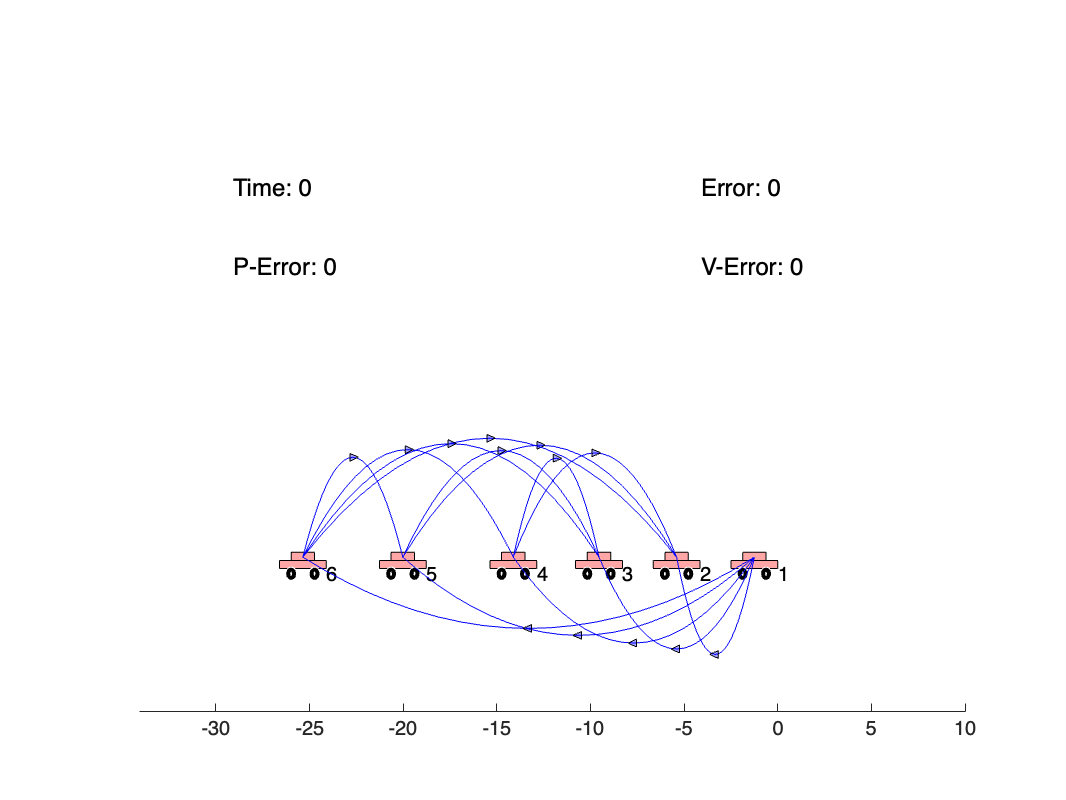


%% Resulting optimal parameters for Centralized case
% pVals = [0.0053    0.0451    0.0444    0.0453    0.0450] % after all tweaks (centralized)
%% Resulting optimal parameters for Decentralized case
% pVals = [0.1995    0.1282    0.2070    0.1636    0.2022] % after all tweaks (centralized)

%% An alternative: Trying some fixed set of parameters.
% pVals = 0.15*ones(numOfPlatoons,max(numOfVehicles));
%% Some other alternatives:
% pVals = [0.0203    0.0203    0.0202    0.0202    0.0204] % with initial condition 0.15
% pVals = [0.0029    0.0029    0.0028    0.0029    0.0029] % with initial condition 0.1


%%% Execution of the controller synthesis
%net.platoons(1).vehicles(2).synthesizeLocalControllers(2,nuBar,rhoBar)
% Actually, above defined nuBar,rhoBar,gammaSqBar are no longer needed

net.loadPlatoonControllers(errorDynamicsType,isCentralized,isDSS,isOnlyStabilizing,gammaSqBar,nuBar,rhoBar,pVals);

%%% In decentralized implementation, there are two things to consider:
% gammaSq_i needs to be costrainted at each subsystem i (or penalized considerably), 
% otherwise it tends to grow with i. Recall that max(gammaSq_i) = gammaSq. 
% There is a zero eigenvalue in the main LMI constraint (this is also in the
% centralized problem). This may be the reason why solver gives "Unknown Status" error.

%%% Graphing the Resulting topology
figure(2)
hold on
ax1 = gca;                   % gca = get current axis handle
ax1.YAxis.Visible = 'off';   % hide out the y-axis from the plot
% axis off
% set(gcf,'Visible','off')
net.drawNetwork(2)

Running the Simulation - Updating the states

% Update the states and plot them in real time as an animation
dt = 0.01;
tMax = 10; 
tArray = 0:dt:tMax;

% Leader's trajectory specification
tVals = tMax*[0,0.2,0.4,0.6,0.8,1];     % Special time instants (inbetween which the acceleration is constant)
vVals = [0,30,40,40,20,20];  % Velocities to be achived at these time instants
net.generateLeadersControlProfiles(dt,tVals,vVals);

% Updating the platoons
for t = tArray

    % Use this update function to achieve the update of the entire program
    net.update(t,dt);
    net.redrawNetwork(2)
    pause(0.01)
    
end

% Plot the state histories
figure
hold on
for k = 1:1:numOfPlatoons
    for i = 1:1:numOfVehicles(k)
        plot(tArray,net.platoons(k).vehicles(i).stateHistory(1,:)','-',DisplayName=['Plat:',num2str(k),'; Vehi:',num2str(i)]);
    end
end
xlabel('$t$/time(s)','Interpreter','latex')
ylabel('$x(t)$/distances(m)','Interpreter','latex')
legend(Location="eastoutside")
grid on 

figure
hold on
for k = 1:1:numOfPlatoons
    for i = 1:1:numOfVehicles(k)
        plot(tArray,net.platoons(k).vehicles(i).stateHistory(2,:)','-',DisplayName=['Plat:',num2str(k),'; Vehi:',num2str(i)]);
    end
end
xlabel('$t$/time(s)','Interpreter','latex')
ylabel('$v(t)$/speed(m/s)','Interpreter','latex')
legend(Location="eastoutside")
grid on 

% Plot the location error histories
figure
hold on
for k = 1:1:numOfPlatoons
    for i = 2:1:numOfVehicles(k)
        plot(tArray,net.platoons(k).vehicles(i).errorHistory(1,:)','-',DisplayName=['Plat:',num2str(k),'; Vehi:',num2str(i)]);
    end
end
xlabel('$t$/time(s)','Interpreter','latex')
ylabel('$\tilde{x}(t)$/location-error(m)','Interpreter','latex')
legend(Location="eastoutside")
grid on 

figure
hold on
for k = 1:1:numOfPlatoons
    for i = 2:1:numOfVehicles(k)
        plot(tArray,net.platoons(k).vehicles(i).errorHistory(2,:)','-',DisplayName=['Plat:',num2str(k),'; Vehi:',num2str(i)]);
    end
end
xlabel('$t$/time(s)','Interpreter','latex')
ylabel('$\tilde{v}(t)$/velocity-error(m/s)','Interpreter','latex')
legend(Location="eastoutside")
grid on 


% Plot the state histories of leaders
figure
hold on
for k = 1:1:numOfPlatoons
    for i = 1
        plot(tArray,net.platoons(k).vehicles(i).stateHistory(1,:)','-',DisplayName=['Plat:',num2str(k),'; Vehi:',num2str(i)]);
    end
end
xlabel('$t$/time(s)','Interpreter','latex')
ylabel('$x(t)$/distances(m)','Interpreter','latex')
legend(Location="eastoutside")
grid on 


figure
hold on
for k = 1:1:numOfPlatoons
    for i = 1
        plot(tArray,net.platoons(k).vehicles(i).stateHistory(2,:)','-',DisplayName=['Plat:',num2str(k),'; Vehi:',num2str(i)]);
    end
end
xlabel('$t$/time(s)','Interpreter','latex')
ylabel('$v(t)$/speed(m/s)','Interpreter','latex')
legend(Location="eastoutside")
grid on 

Ideas to pursue next:

What is the best set of passivity information for this topology synthesis?

Leader's connection design (Centralized Setting, ED-I)

For the case with z = C e

Local controller design for passivation